# Codes for *Parameter Estimation from ICC Curves* 

Author: Joceline Lega - Last modified: 03/28/2021

Please cite EpiGro v.2, [https://jocelinelega.github.io/EpiGro/,](https://jocelinelega.github.io/EpiGro/,) as well as J. Lega, *Parameter Estimation from ICC Curves*, J. Biological Dynamics (2021) when reusing this work.

## Figures 1 and S3

Defining $s = S/N,$ $i = I/N,$ and $r = R/N,$ as the expected sizes of the susceptible ($S$), infected ($I$), and recovered ($R$) compartments relative to the total population $N,$ so that $s + i + r = 1,$ the SIR model is given by 


$$\frac{ds}{dt}= - \beta s i; \quad \frac{di}{dt}= \beta s i - \gamma i; \quad \frac{dr}{dt}= \gamma i,$$


where $\beta$ is the contact rate of the disease and $\gamma$ is its recovery rate. Scaling time by $\tau = 1/\gamma$ turns the SIR model into a one-parameter ($R_0$) model, where $R_0 = \beta / \gamma$ is the basic reproductive ratio.

The ICC curve of the SIR model with initial condition described by the parameter $\kappa = \frac{S(0)}{N} = 1 - \frac{C(0)}{N}$ is given by


$${\cal I} = \frac{d C}{d t} = \beta \left(C + \frac{N}{R_0} \ln\left(1 - \frac{C}{N}\right) - \frac{N}{R_0} \ln(\kappa) \right) \left(1 - \frac{C}{N} \right).$$


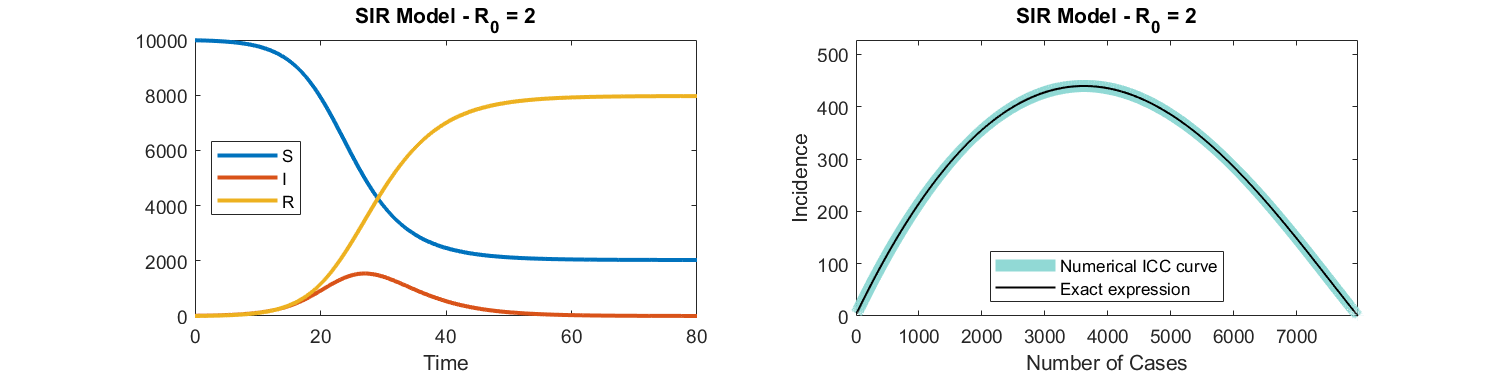

% Parameters
clear variables;
N=10000;
beta=0.5; gam1=0.5/2; r01=beta/gam1; gam2=0.5/10.5; r02=beta/gam2;
i0=0.001; t0=0; last_week=700; dt=0.1;
options = odeset('RelTol',1e-8,'AbsTol',1e-10);

% Integrate model
[s1,q1]=ode45(@(t,y)SIR(t,y,beta,gam1,N),t0:dt:last_week,...
    [(1-i0)*N,i0*N,0],options);
[s2,q2]=ode45(@(t,y)SIR(t,y,beta,gam2,N),t0:dt:last_week,...
    [(1-i0)*N,i0*N,0],options);

% ICC curve
C1R=q1(:,2)+q1(:,3); In1=beta*q1(:,1).*q1(:,2)/N;
%M=max(I); C0=max(C)/2; h0=M/C0^2;
kappa1=q1(1,1)/N*exp(r01*q1(1,3)/N);
IC1 = beta*(N/r01*log(1-C1R/N)-N/r01*log(kappa1)+C1R).*(1-C1R/N);
C2R=q2(:,2)+q2(:,3); In2=beta*q2(:,1).*q2(:,2)/N;
%M=max(I); C0=max(C)/2; h0=M/C0^2;
kappa2=q2(1,1)/N*exp(r02*q2(1,3)/N);
IC2 = beta*(N/r02*log(1-C2R/N)-N/r02*log(kappa2)+C2R).*(1-C2R/N);

% Plots
figure(); set(gcf,'Position',[50 50 1000 250]);
subplot(1,2,1); plot(s1,q1(:,1),s1,q1(:,2),s1,q1(:,3),'LineWidth',2);
legend('S','I','R','Location','west'); xlabel('Time'); xlim([0 80])
title(['SIR Model - R_0 = ' num2str(r01)],'FontSize',10)
subplot(1,2,2); plot(C1R,In1,'Color',[146/256 218/256 214/256],...
    'LineWidth',6)
hold on; plot(C1R,IC1,'k-','LineWidth',1); hold off
xlim([0 max(C1R)]); ylim([0 1.2*(max(In1))]); xlabel('Number of Cases');
ylabel('Incidence')
title(['SIR Model - R_0 = ' num2str(r01)],'FontSize',10)
legend('Numerical ICC curve','Exact expression','Location','South')

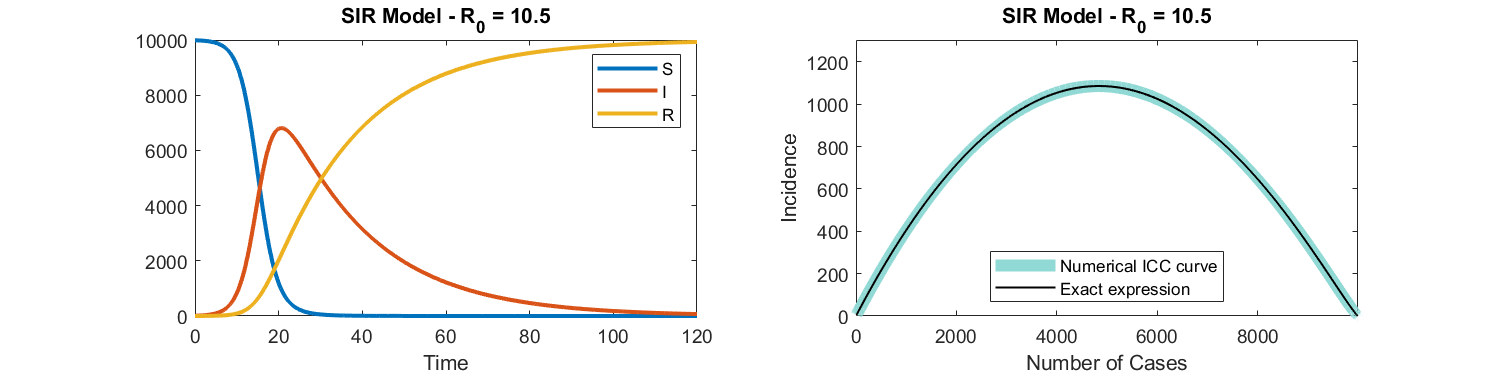

figure(); set(gcf,'Position',[50 50 1000 250]);
subplot(1,2,1); plot(s2,q2(:,1),s2,q2(:,2),s2,q2(:,3),'LineWidth',2);
legend('S','I','R'); xlabel('Time'); xlim([0 120])
title(['SIR Model - R_0 = ' num2str(r02)],'FontSize',10)
subplot(1,2,2); plot(C2R,In2,'Color',[146/256 218/256 214/256],...
    'LineWidth',6)
hold on; plot(C2R,IC2,'k-','LineWidth',1); hold off
xlim([0 max(C2R)]); ylim([0 1.2*(max(In2))]); xlabel('Number of Cases');
ylabel('Incidence')
title(['SIR Model - R_0 = ' num2str(r02)],'FontSize',10)
legend('Numerical ICC curve','Exact expression','Location','South')

## Figure 2

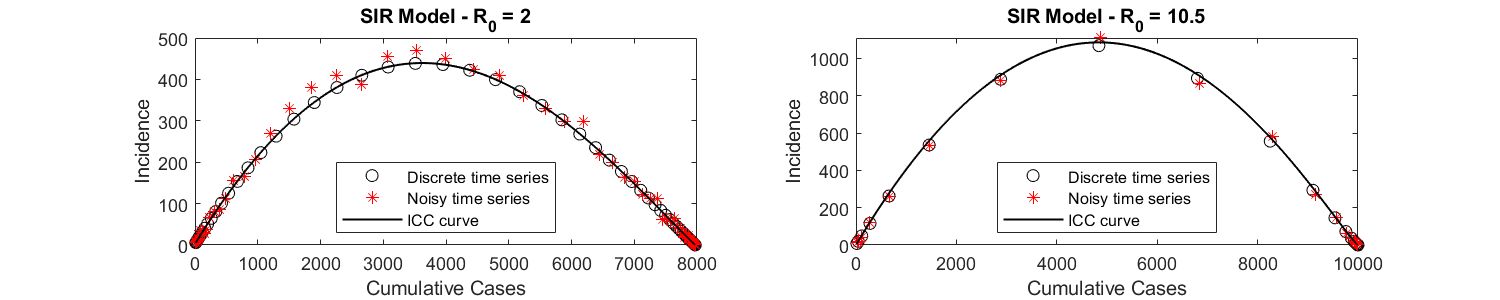

% Exact time series, with a time step equal to 1
dt1=1; T1=0:dt1:100; k=ismember(s1,T1); S1=q1(k,1); I1=q1(k,2);
R1=q1(k,3);
dt2=2; T2=0:dt2:100; k=ismember(s2,T2); S2=q2(k,1); I2=q2(k,2);
R2=q2(k,3);
% Modify discrete incidence according to a Poisson distribution
% Note that the effectof the noise depends on N, as described above
DC1=I1+R1; DC2=I2+R2; % Discretized cumulative cases
DIn1=DC1; DIn1(2:end)=DC1(2:end)-DC1(1:end-1); DIn2=DC2;
DIn2(2:end)=DC2(2:end)-DC2(1:end-1); % Discretized incidence
rng default % For reproducibility
DIn1N = poissrnd(DIn1); DIn1N(1)=DIn1(1);
DIn2N = poissrnd(DIn2); DIn2N(1)=DIn2(1); % Noisy incidence
% Enforce same total number of cases at the end of the outbreak
DIn1N=DIn1N*DC1(end)/sum(DIn1N); DIn2N=DIn2N*DC2(end)/sum(DIn2N);
% Calculate cumulative number of cases
DICC1=cumsum(DIn1); DICC1N=cumsum(DIn1N);
DICC2=cumsum(DIn2); DICC2N=cumsum(DIn2N);
% ICC curves without interpolation from discrete data
C01=(DICC1(1:end-1)+DICC1(2:end))/2; I01=DIn1(2:end)/dt1;
C1=(DICC1N(2:end)+DICC1N(1:end-1))/2; I1=DIn1N(2:end)/dt1;
C02=(DICC2(1:end-1)+DICC2(2:end))/2; I02=DIn2(2:end)/dt2;
C2=(DICC2N(2:end)+DICC2N(1:end-1))/2; I2=DIn2N(2:end)/dt2;
figure(); set(gcf,'Position',[50 50 1000 200]);
subplot(1,2,1); plot(C01,I01,'ko',C1,I1,'r*'); hold on;
plot(C1R,IC1,'k-','LineWidth',1); hold off;
xlabel('Cumulative Cases'); ylabel('Incidence');
legend('Discrete time series','Noisy time series','ICC curve',...
    'Location','South');
title(['SIR Model - R_0 = ' num2str(r01)])
subplot(1,2,2); plot(C02,I02,'ko',C2,I2,'r*'); hold on;
plot(C2R,IC2,'k-','LineWidth',1); hold off;
xlabel('Cumulative Cases'); ylabel('Incidence');
legend('Discrete time series','Noisy time series','ICC curve',...
    'Location','South');
title(['SIR Model - R_0 = ' num2str(r02)])

## **Figures 3 & 4**

**Poisson-distributed incidence.** We plot below the distributions of $\beta_m,$ $\gamma_m,$ and $R_{0m} = \frac{\beta_m}{\gamma_m}$ obtained from 100,000 noisy realization of the reference simulations with $R_0 = 2$ and $R_0 = 10.5.$

new_run=0; N_run=100000;
if new_run==1
    bet=zeros(1,N_run); gam=bet; mn=bet; vn=bet; zn=bet;
    for j=1:N_run
        [bet(j),gam(j),mn(j),vn(j),zn(j)]=...
            find_param_Poisson(DC1,DIn1,dt1,N);
    end
    bet1=bet; gam1=gam; mn1=mn; vn1=vn; zn1=zn;
    save(['./Data_files/SIR_' num2str(r01) '_param_Poisson_' ...
        num2str(N_run) '.mat'],...
        'N','bet1','gam1','mn1','vn1','zn1');
    bet=zeros(1,N_run); gam=bet; mn=bet; vn=bet; zn=bet;
    for j=1:N_run
        [bet(j),gam(j),mn(j),vn(j),zn(j)]=...
            find_param_Poisson(DC2,DIn2,dt2,N);
    end
    bet2=bet; gam2=gam; mn2=mn; vn2=vn; zn2=zn;
    save(['./Data_files/SIR_' num2str(r02) '_param_Poisson_' ...
        num2str(N_run) '.mat'],...
        'N','bet2','gam2','mn2','vn2','zn2');
else
    load(['./Data_files/SIR_' num2str(r01) '_param_Poisson_' ...
        num2str(N_run) '.mat'],'bet1','gam1','zn1');
    load(['./Data_files/SIR_' num2str(r02) '_param_Poisson_' ...
        num2str(N_run) '.mat'],'bet2','gam2','zn2');
end

**Distributions for **$R_0 = 2.$

disp(['R_0 = ' num2str(r01)])

R_0 = 2


disp(['<p> = ' num2str(mean(zn1)) '; var(p) = ' num2str(var(zn1))])

<p> = -0.00094155; var(p) = 4.9513e-07


figure(); set(gcf,'Position',[50 50 1000 200]);
subplot(1,3,1); edges = [0 0.45:0.1/30:0.55 1];
histogram(bet1,edges,'Normalization','pdf');
xlabel('\beta_c'); ylabel('Density')
xlim([0.45 0.55]); disp(['< \beta_c > = ' num2str(mean(bet1)) ...
    '; std(\beta_c) = ' num2str(std(bet1))]);

< \beta_c > = 0.49936; std(\beta_c) = 0.0060199


subplot(1,3,2); edges = [0 0.23:0.04/30:0.27 1];
histogram(gam1,edges,'Normalization','pdf'); xlabel('\gamma_c'); 
xlim([0.23 0.27]); disp(['< \gamma_c > = ' num2str(mean(gam1)) ...
    '; std(\gamma_c) = ' num2str(std(gam1))]);

< \gamma_c > = 0.24967; std(\gamma_c) = 0.0030162


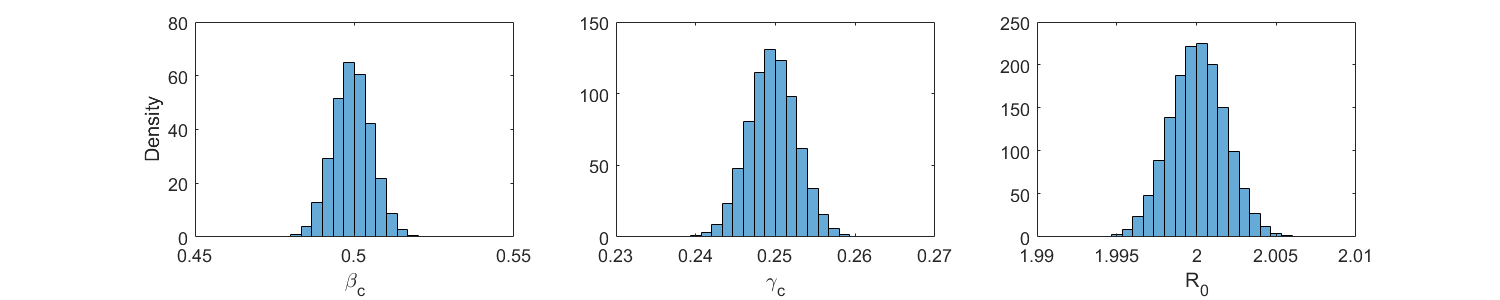

< R_{0} > = 2.0001; std(R_0) = 0.001732


subplot(1,3,3); edges = [0 1.99:0.02/30:2.01 10];
histogram(bet1./gam1,edges,'Normalization','pdf'); xlabel('R_0'); 
xlim([1.99 2.01]); disp(['< R_{0} > = ' num2str(mean(bet1./gam1)) ...
    '; std(R_0) = ' num2str(std(bet1./gam1))]);

disp(['<beta>/<gamma> = ' num2str(mean(bet1)/mean(gam1))])

<beta>/<gamma> = 2.0001


**Distributions for **$R_0 = 10.5.$

disp(['R_0 = ' num2str(r02)])

R_0 = 10.5


disp(['<p> = ' num2str(mean(zn2)) '; var(p) = ' num2str(var(zn2))])

<p> = 0.0078884; var(p) = 3.6167e-05


figure(); set(gcf,'Position',[50 50 1000 200]);
subplot(1,3,1); edges = [0 0.45:0.1/30:0.55 1];
histogram(bet2,edges,'Normalization','pdf');
xlabel('\beta_c'); ylabel('Density')
xlim([0.45 0.55]); disp(['< \beta_c > = ' num2str(mean(bet2)) ...
    '; std(\beta_c) = ' num2str(std(bet2))]);

< \beta_c > = 0.49355; std(\beta_c) = 0.012035


subplot(1,3,2); edges = [0 0:0.1/30:0.1 1];
histogram(gam2,edges,'Normalization','pdf'); xlabel('\gamma_c'); 
xlim([0 0.1]); disp(['< \gamma_c > = ' num2str(mean(gam2)) ...
    '; std(\gamma_c) = ' num2str(std(gam2))]);

< \gamma_c > = 0.049477; std(\gamma_c) = 0.0069525


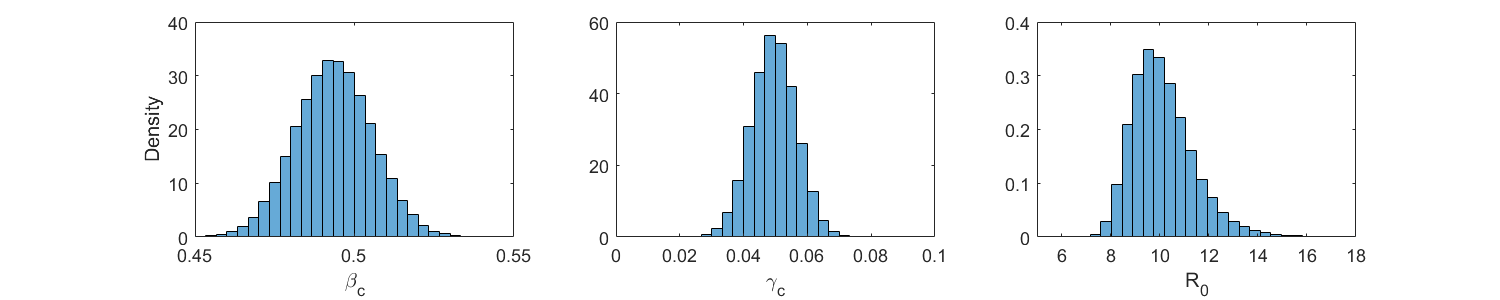

< R_{0} > = 10.152; std(R_0) = 1.2935


subplot(1,3,3); edges = [0 5:13/30:18 50];
histogram(bet2./gam2,edges,'Normalization','pdf'); xlabel('R_0'); 
xlim([5 18]); disp(['< R_{0} > = ' num2str(mean(bet2./gam2)) ...
    '; std(R_0) = ' num2str(std(bet2./gam2))]);

disp(['<beta>/<gamma> = ' num2str(mean(bet2)/mean(gam2))])

<beta>/<gamma> = 9.9752


## **Figure 5**

**Normally-distributed noise.** We plot below the distributions of $\beta_m,$ $\gamma_m,$ and $R_{0m} = \frac{\beta_m}{\gamma_m}$ obtained from 100,000 noisy realization of the reference simulations with $R_0 = 10.5$ and $R_0 = 2.$ We show results for 3 different values of the amplitude of the multiplicative noise (5%, 15%, 25%). Realizations leading to negative values of $\gamma$ are considered unrealistic and discarded.

new_run=0; N_run=100000;
if new_run==1
    noise_size=[0.05 0.15 0.25];
    bet=zeros(length(noise_size),N_run); gam=bet;
    mn=bet; vn=bet; zn=vn;
    for j=1:N_run
        for k=1:length(noise_size)
            [bet(k,j),gam(k,j),mn(k,j),vn(k,j),zn(k,j)]=...
                find_param_Normal(DC1,DIn1,dt1,N,noise_size(k));
        end
    end
    bet1=bet; gam1=gam; mn1=mn; vn1=vn; zn1=zn;
    save(['./Data_files/SIR_' num2str(r01) '_param_Normal_' ...
        num2str(N_run) '.mat'],'N','bet1',...
        'gam1','mn1','vn1','zn1','noise_size');
    bet=zeros(length(noise_size),N_run); gam=bet; mn=bet; vn=bet; zn=vn;
    for j=1:N_run
        for k=1:length(noise_size)
            [bet(k,j),gam(k,j),mn(k,j),vn(k,j),zn(k,j)]=...
                find_param_Normal(DC2,DIn2,dt2,N,noise_size(k));
        end
    end
    bet2=bet; gam2=gam; mn2=mn; vn2=vn; zn2=zn;
    save(['./Data_files/SIR_' num2str(r02) '_param_Normal_' ...
        num2str(N_run) '.mat'],'N','bet2',...
        'gam2','mn2','vn2','zn2','noise_size');
else
    load(['./Data_files/SIR_' num2str(r01) '_param_Normal_' ...
        num2str(N_run) '.mat'],'bet1',...
        'gam1','mn1','vn1','zn1');
    load(['./Data_files/SIR_' num2str(r02) '_param_Normal_' ...
        num2str(N_run) '.mat'],'bet2',...
        'gam2','mn2','vn2','zn2','noise_size');
end

**Distributions for **$R_0 = 2.$

disp(['R_0 = ' num2str(r01)])

R_0 = 2


disp(['<p> = ' num2str(mean(zn1,2)') '; var(p) = ' ...
    num2str(var(zn1,[],2)')])

<p> = -0.00090083 -0.00083999 -0.00078372; var(p) = 2.0934e-07   2.094e-06  6.5779e-06


figure(); set(gcf,'Position',[50 50 1000 200]);
subplot(1,3,1); edges = [-3 0.4:0.2/30:0.6 2];
histogram(bet1(1,:),edges,'Normalization','pdf'); hold on;
histogram(bet1(2,:),edges,'Normalization','pdf');
histogram(bet1(3,:),edges,'Normalization','pdf'); hold off;
xlim([0.4 0.6]); xlabel('\beta_c'); ylabel('Density')
disp(['< \beta_m > = [' num2str([mean(bet1(1,:)) mean(bet1(2,:)) ...
    mean(bet1(3,:))]) ']']);

< \beta_m > = [0.49942     0.50007      0.5013]


disp(['std(\beta_m) = [' num2str([std(bet1(1,:)) std(bet1(2,:)) ...
    std(bet1(3,:))]) ']']);

std(\beta_m) = [0.0047736    0.015156    0.026683]


legend(num2str(noise_size(1)),num2str(noise_size(2)),...
    num2str(noise_size(3)))
subplot(1,3,2); edges = [-1 0.2:0.1/30:0.3 1];
histogram(gam1(1,:),edges,'Normalization','pdf'); hold on;
histogram(gam1(2,:),edges,'Normalization','pdf');
histogram(gam1(3,:),edges,'Normalization','pdf'); hold off;
legend(num2str(noise_size(1)),num2str(noise_size(2)),...
    num2str(noise_size(3)))
xlim([0.2 0.3]); xlabel('\gamma_c');
disp(['< \gamma_m > = [' num2str([mean(gam1(1,:)) mean(gam1(2,:)) ...
    mean(gam1(3,:))]) ']']);

< \gamma_m > = [0.2497     0.25002     0.25063]


disp(['std(\gamma_m) = [' num2str([std(gam1(1,:)) std(gam1(2,:)) ...
    std(gam1(3,:))]) ']']);

std(\gamma_m) = [0.0024084   0.0076474     0.01346]


subplot(1,3,3); edges = [-10 1.98:0.04/30:2.02 10];
histogram(bet1(1,:)./gam1(1,:),edges,'Normalization','pdf'); hold on;
histogram(bet1(2,:)./gam1(2,:),edges,'Normalization','pdf');
histogram(bet1(3,:)./gam1(3,:),edges,'Normalization','pdf'); hold off;
xlim([1.98 2.02]); xlabel('R_0');
disp(['< R_{0m} > = [' num2str([mean(bet1(1,:)./gam1(1,:)) ...
    mean(bet1(2,:)./gam1(2,:)) mean(bet1(3,:)./gam1(3,:))]) ']']);

< R_{0m} > = [2.0001      2.0002      2.0002]


disp(['std(R_{0m}) = [' num2str([std(bet1(1,:)./gam1(1,:)) ...
    std(bet1(2,:)./gam1(2,:)) std(bet1(3,:)./gam1(3,:))]) ']']);

std(R_{0m}) = [0.0008971   0.0028407   0.0050217]


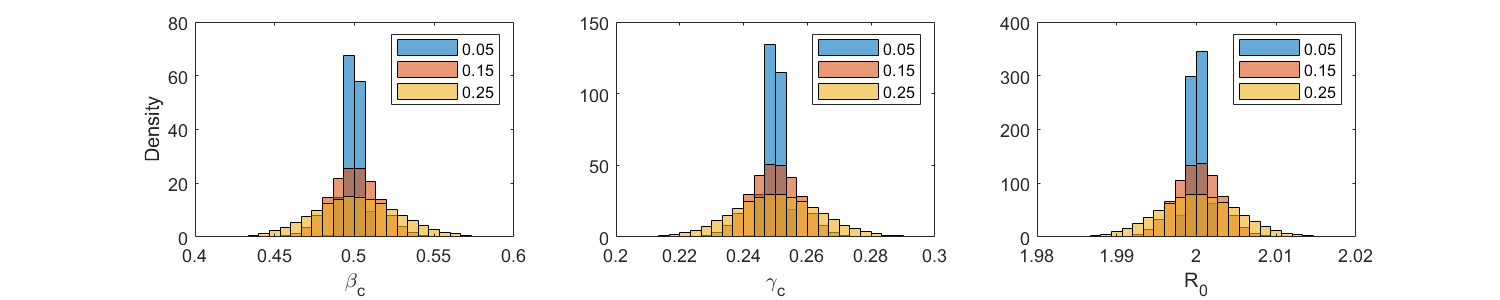

legend(num2str(noise_size(1)),num2str(noise_size(2)),...
    num2str(noise_size(3)))

disp(['<beta>/<gamma> = [' num2str([mean(bet1(1,:))/mean(gam1(1,:)) ...
    mean(bet1(2,:))/mean(gam1(2,:)) ...
    mean(bet1(3,:))/mean(gam1(3,:))]) ']'])

<beta>/<gamma> = [2.0001      2.0001      2.0002]


**Distributions for **$R_0 = 10.5.$

disp(['R_0 = ' num2str(r02)])

R_0 = 10.5


disp(['<p> = ' num2str(mean(zn2,2)') '; var(p) = ' ...
    num2str(var(zn2,[],2)')])

<p> = 0.0077874    -0.01586    -0.01329; var(p) = 8.05234e-05      9.79133      12.5097


figure(); set(gcf,'Position',[50 50 1000 200]);
subplot(1,3,1); edges = [-3 0.3:0.6/30:0.9 2];
histogram(bet2(1,:),edges,'Normalization','pdf'); hold on;
histogram(bet2(2,:),edges,'Normalization','pdf');
histogram(bet2(3,:),edges,'Normalization','pdf'); hold off;
xlim([0.3 0.9]); xlabel('\beta_c'); ylabel('Density')
disp(['< \beta_m > = [' num2str([mean(bet2(1,:)) mean(bet2(2,:)) ...
    mean(bet2(3,:))]) ']']);

< \beta_m > = [0.49387     0.50531      0.5396]


disp(['std(\beta_m) = [' num2str([std(bet2(1,:)) std(bet2(2,:)) ...
    std(bet2(3,:))]) ']']);

std(\beta_m) = [0.020115    0.057717    0.093841]


legend(num2str(noise_size(1)),num2str(noise_size(2)),...
    num2str(noise_size(3)))
subplot(1,3,2); edges = [-1 0:0.25/30:0.25 1];
histogram(gam2(1,:),edges,'Normalization','pdf'); hold on;
histogram(gam2(2,:),edges,'Normalization','pdf');
histogram(gam2(3,:),edges,'Normalization','pdf'); hold off;
legend(num2str(noise_size(1)),num2str(noise_size(2)),...
    num2str(noise_size(3)))
xlim([0 0.25]); xlabel('\gamma_c');
disp(['< \gamma_m > = [' num2str([mean(gam2(1,:)) mean(gam2(2,:)) ...
    mean(gam2(3,:))]) ']']);

< \gamma_m > = [0.049607    0.054964    0.071668]


disp(['std(\gamma_m) = [' num2str([std(gam2(1,:)) std(gam2(2,:)) ...
    std(gam2(3,:))]) ']']);

std(\gamma_m) = [0.010358    0.029308     0.04648]


subplot(1,3,3); edges = [-1 1:40/30:40 50];
histogram(bet2(1,:)./gam2(1,:),edges,'Normalization','pdf'); hold on;
histogram(bet2(2,:)./gam2(2,:),edges,'Normalization','pdf');
histogram(bet2(3,:)./gam2(3,:),edges,'Normalization','pdf'); hold off;
xlim([1 40]); xlabel('R_0');
disp(['< R_{0m} > = [' num2str([mean(bet2(1,:)./gam2(1,:)) ...
    mean(bet2(2,:)./gam2(2,:)) mean(bet2(3,:)./gam2(3,:))]) ']']);

< R_{0m} > = [10.3682       27.095      29.9396]


disp(['std(R_{0m}) = [' num2str([std(bet2(1,:)./gam2(1,:)) ...
    std(bet2(2,:)./gam2(2,:)) std(bet2(3,:)./gam2(3,:))]) ']']);

std(R_{0m}) = [2.14084      769.7694      863.8633]


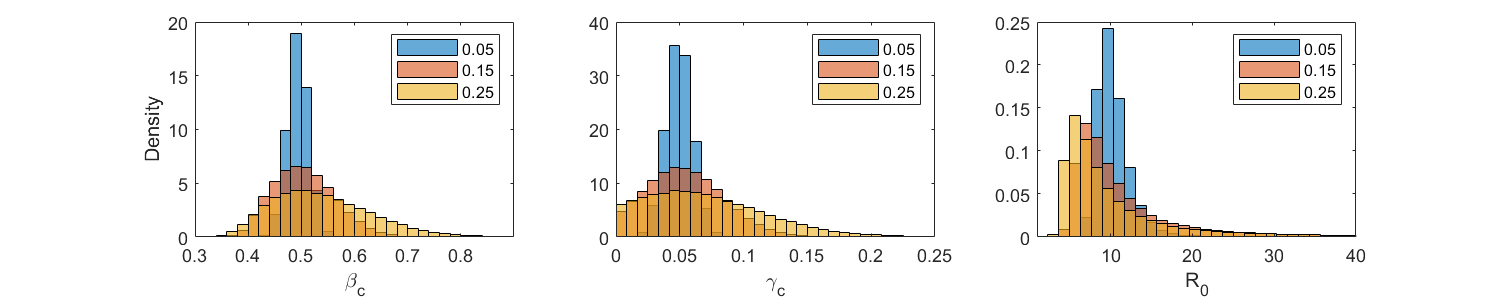

legend(num2str(noise_size(1)),num2str(noise_size(2)),...
    num2str(noise_size(3)))

disp(['<beta>/<gamma> = [' num2str([mean(bet2(1,:))/mean(gam2(1,:)) ...
    mean(bet2(2,:))/mean(gam2(2,:)) ...
    mean(bet2(3,:))/mean(gam2(3,:))]) ']'])

<beta>/<gamma> = [9.9556      9.1935      7.5292]


## Figures S1 & 6A

In this section, we use the formuas for $\beta_m$ and $\gamma_m$ given above, but change the value of $M,$ the number of terms in the sums that appear in Equation (3). Until now, we used the full set of points obtained from the discretization of the simulated SIR dynamics. Reducing the value of $M$amounts to estimating the parameters before an outbreak has finished its course. The associated uncertainty is thus expected to increase as the number of data points included in each estimation is decreased. To test this, we simulate 50,000 realizations of an outbreak, with the two different types of noise introduced above to represent reporting error, and follow the evolution of the distributions of the estimated parameters as $M$ increases. For $R_0 = 10.5,$ the outbreak has run its course after $t_{end} = 120$ units of time, and we have assumed we have $M_{max} = 80$ data points, with consecutive values separated by 2 units of time (which could be a day or a week depending on the disease). For $R_0 = 2,$ we pick $t_{end} = 60$ (see plots of cumulative cases above), and we have $M_{max} = 40$ data points, one every 1 units of time.

$R_0 = 2$** with Poisson-distributed noise**

rng default % For reproducibility
new_run=0; N_run=50000;
if new_run==1
    DC1_ref=DC1(T1<=40); DIn1_ref=DIn1(T1<=40);
    DIn1_pert=zeros(N_run,length(DIn1_ref));
    for j=1:N_run
        % Noisy incidence
        DIn1_pert(j,:)=poissrnd(DIn1_ref);
        DIn1_pert(1)=DIn1_ref(1);
        % Enforce same total number of cases at the end of the outbreak
        DIn1_pert(j,:)=DIn1_pert(j,:)*DC1_ref(end)/sum(DIn1_pert(j,:));
    end
    M=5:4:length(DC1_ref); bet1=zeros(size(DIn1_pert,1),length(M));
    gam1=bet1;
    for j=1:size(bet1,1)
        for k=1:length(M)
            DInN=DIn1_pert(j,1:M(k));
            DICCN=cumsum(DInN);
            C=(DICCN(2:end)+DICCN(1:end-1))/2; I=DInN(2:end)/dt1;
            [bet1(j,k),gam1(j,k),~,~]=find_beta_gamma_z(C,I,N);
        end
    end
    save(['./Data_files/SIR_' num2str(r01) '_realizations_Poisson_' ...
        num2str(N_run) '.mat'],...
        'DC1_ref','DIn1_ref','DIn1_pert','T1','M','bet1','gam1');
else
    load(['./Data_files/SIR_' num2str(r01) '_realizations_Poisson_' ...
        num2str(N_run) '.mat'],...
        'T1','M','bet1','gam1');
end

The plots below show the distributions of $\beta_m,$ $\gamma_m,$ and $R_{0m} = \frac{\beta_m}{\gamma_m}$ at different time points.

**Temporal dependence of **$\beta_m$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges=[-100 -60:4:60 100];
histogram(bet1(:,1),edges,'Normalization','pdf'); hold on;
histogram(bet1(:,2),edges,'Normalization','pdf');
histogram(bet1(:,3),edges,'Normalization','pdf'); hold off;
xlabel('\beta_c'); xlim([-60 60]); ylabel('Density')
disp(['< beta_c > = [' num2str([mean(bet1(:,1)) mean(bet1(:,2)) ...
    mean(bet1(:,3))]) ']']);

< beta_c > = [14.3267      1.65423     0.599515]


legend(['T_m = ' num2str(T1(M(1)))],['T_m = ' num2str(T1(M(2)))],...
    ['T_m = ' num2str(T1(M(3)))],'Location','northwest')
subplot(1,3,2); edges = [-10 -2:5/30:3 10];
histogram(bet1(:,4),edges,'Normalization','pdf'); hold on;
histogram(bet1(:,5),edges,'Normalization','pdf');
histogram(bet1(:,6),edges,'Normalization','pdf'); hold off; xlim([-2 3]);
xlabel('\beta_c');
disp(['< beta_c > = [' num2str([mean(bet1(:,4)) mean(bet1(:,5)) ...
    mean(bet1(:,6))]) ']']);

< beta_c > = [0.50016     0.49674     0.49768]


legend(['T_m = ' num2str(T1(M(4)))],['T_m = ' num2str(T1(M(5)))],...
    ['T_m = ' num2str(T1(M(6)))],'Location','northeast')
subplot(1,3,3); edges = [-10 0.4:0.2/30:0.6 10];
histogram(bet1(:,7),edges,'Normalization','pdf'); hold on;
histogram(bet1(:,8),edges,'Normalization','pdf');
histogram(bet1(:,9),edges,'Normalization','pdf'); hold off; xlim([0.4 0.6]);
xlabel('\beta_c');
disp(['< beta_c > = [' num2str([mean(bet1(:,7)) mean(bet1(:,8)) ...
    mean(bet1(:,9))]) ']']);

< beta_c > = [0.49904     0.49942     0.49946]


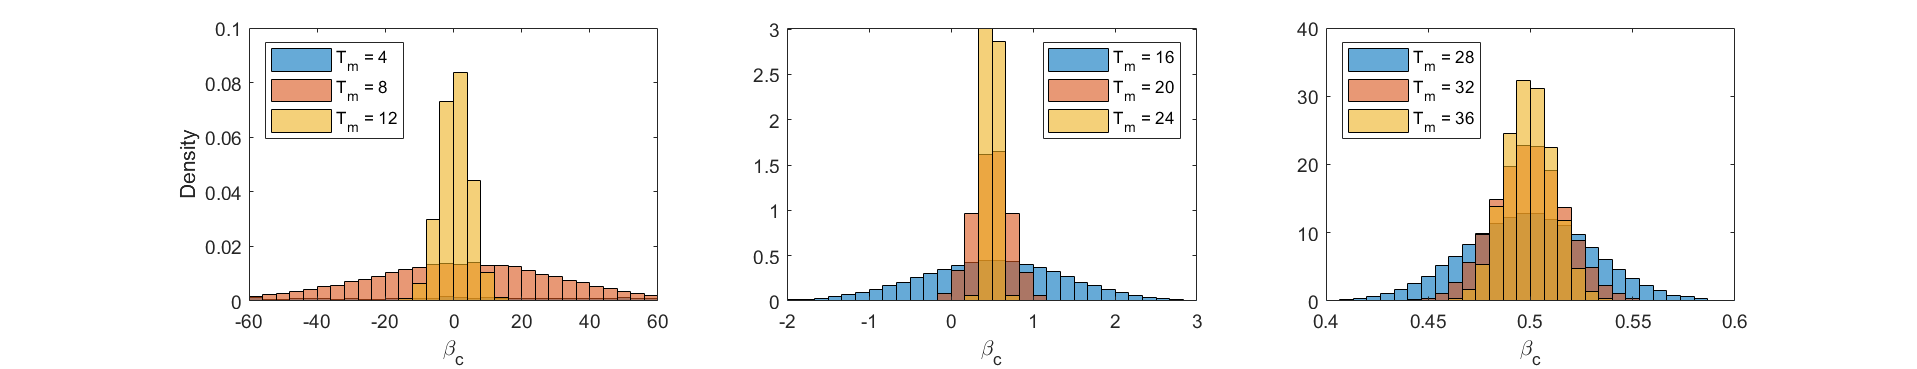

legend(['T_m = ' num2str(T1(M(7)))],['T_m = ' num2str(T1(M(8)))],...
    ['T_m = ' num2str(T1(M(9)))],'Location','northwest')

**Temporal dependence of **$\gamma_m$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges =[-100 -60:4:60 100];
histogram(gam1(:,1),edges,'Normalization','pdf'); hold on;
histogram(gam1(:,2),edges,'Normalization','pdf');
histogram(gam1(:,3),edges,'Normalization','pdf'); hold off;
xlabel('\gamma_c'); xlim([-60 60]); ylabel('Density');
disp(['< gamma_c > = [' num2str([mean(gam1(:,1)) ...
    mean(gam1(:,2)) mean(gam1(:,3))]) ']']);

< gamma_c > = [14.0356      1.39549     0.348198]


legend(['T_m = ' num2str(T1(M(1)))],['T_m = ' num2str(T1(M(2)))],...
    ['T_m = ' num2str(T1(M(3)))],'Location','northwest')
subplot(1,3,2); edges = [-3 -2:4/30:2 3];
histogram(gam1(:,4),edges,'Normalization','pdf'); hold on;
histogram(gam1(:,5),edges,'Normalization','pdf');
histogram(gam1(:,6),edges,'Normalization','pdf'); hold off;
xlim([-2 2]); xlabel('\gamma_c');
disp(['< gamma_c > = [' num2str([mean(gam1(:,4)) ...
    mean(gam1(:,5)) mean(gam1(:,6))]) ']']);

< gamma_c > = [0.25062     0.24735     0.24822]


legend(['T_m = ' num2str(T1(M(4)))],['T_m = ' num2str(T1(M(5)))],...
    ['T_m = ' num2str(T1(M(6)))],'Location','northwest')
subplot(1,3,3); edges = [-1 0.15:0.2/30:0.35 1];
histogram(gam1(:,7),edges,'Normalization','pdf'); hold on;
histogram(gam1(:,8),edges,'Normalization','pdf');
histogram(gam1(:,9),edges,'Normalization','pdf'); hold off;
xlim([0.15 0.35]); xlabel('\gamma')
disp(['< gamma_c > = [' num2str([mean(gam1(:,7)) ...
    mean(gam1(:,8)) mean(gam1(:,9))]) ']']);

< gamma_c > = [0.24939      0.2497     0.24973]


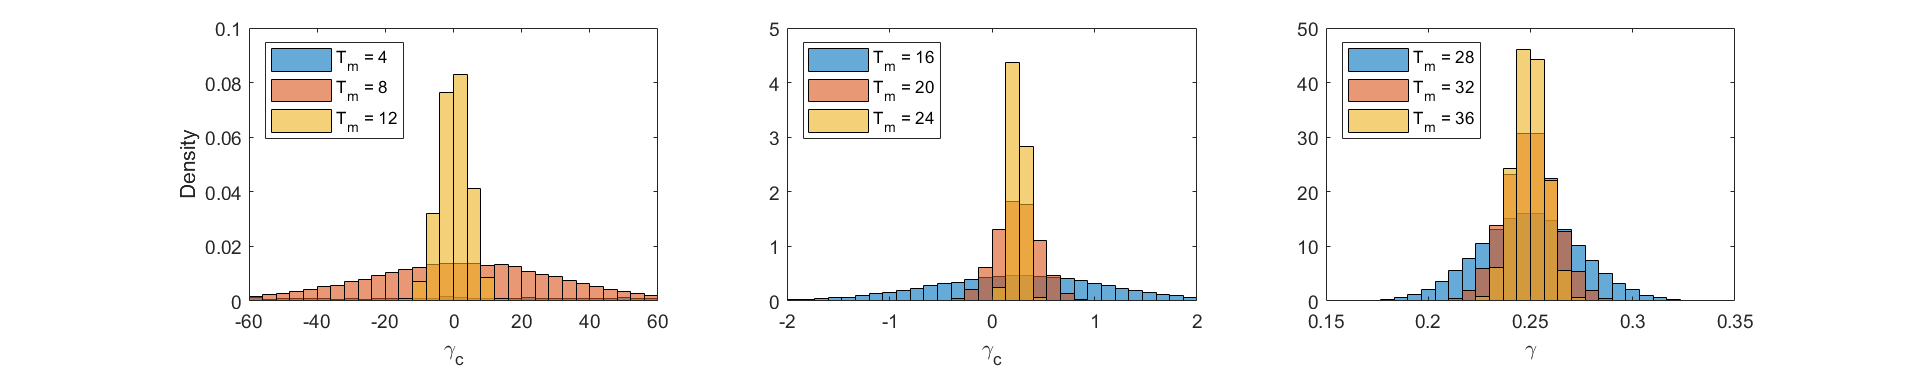

legend(['T_m = ' num2str(T1(M(7)))],['T_m = ' num2str(T1(M(8)))],...
    ['T_m = ' num2str(T1(M(9)))],'Location','northwest')

**Temporal dependence of **$R_0$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges = [-20 -3:6/30:3 20];
histogram(bet1(:,1)./gam1(:,1),edges,'Normalization','pdf'); hold on;
histogram(bet1(:,1)./gam1(:,2),edges,'Normalization','pdf');
histogram(bet1(:,3)./gam1(:,3),edges,'Normalization','pdf'); hold off;
xlim([-3 3]); xlabel('R_0'); ylabel('Density')
disp(['< R_0 > = [' num2str([mean(bet1(:,1)./gam1(:,1)) ...
    mean(bet1(:,2)./gam1(:,2)) mean(bet1(:,3)./gam1(:,3))]) ']']);

< R_0 > = [0.99923     0.96164     0.82565]


legend(['T_m = ' num2str(T1(M(1)))],['T_m = ' num2str(T1(M(2)))],...
    ['T_m = ' num2str(T1(M(3)))],'Location','northwest')
subplot(1,3,2); edges = [-10 -3:11/30:8 50];
histogram(bet1(:,4)./gam1(:,4),edges,'Normalization','pdf'); hold on;
histogram(bet1(:,5)./gam1(:,5),edges,'Normalization','pdf');
histogram(bet1(:,6)./gam1(:,6),edges,'Normalization','pdf');
hold off; xlim([-3 8]); xlabel('R_0');
disp(['< R_0 > = [' num2str([mean(bet1(:,4)./gam1(:,4)) ...
    mean(bet1(:,5)./gam1(:,5)) mean(bet1(:,6)./gam1(:,6))]) ']']);

< R_0 > = [0.72603      2.8828      2.0783]


legend(['T_m = ' num2str(T1(M(4)))],['T_m = ' num2str(T1(M(5)))],...
    ['T_m = ' num2str(T1(M(6)))],'Location','northeast')
subplot(1,3,3); edges = [-10 1.8:0.5/30:2.3 50];
histogram(bet1(:,7)./gam1(:,7),edges,'Normalization','pdf'); hold on;
histogram(bet1(:,8)./gam1(:,8),edges,'Normalization','pdf');
histogram(bet1(:,9)./gam1(:,9),edges,'Normalization','pdf'); hold off;
xlim([1.8 2.3]); xlabel('R_0');
disp(['< R_0 > = [' num2str([mean(bet1(:,7)./gam1(:,7)) ...
    mean(bet1(:,8)./gam1(:,8)) mean(bet1(:,9)./gam1(:,9))]) ']']);

< R_0 > = [2.0084      2.0017      2.0005]


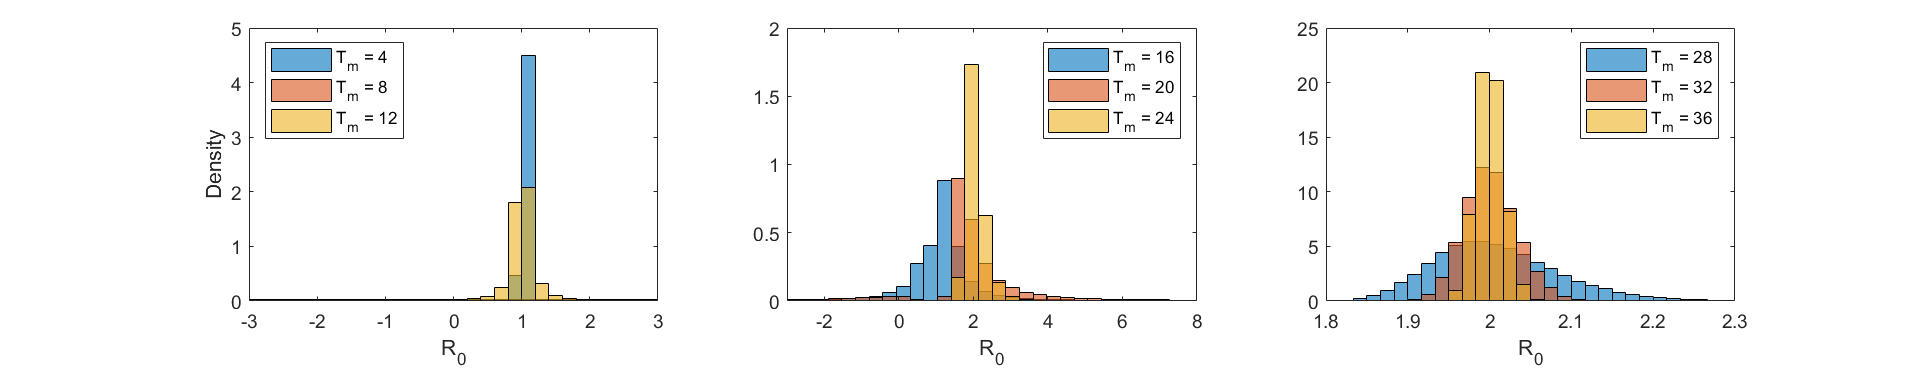

legend(['T_m = ' num2str(T1(M(7)))],['T_m = ' num2str(T1(M(8)))],...
    ['T_m = ' num2str(T1(M(9)))],'Location','northeast')

**Temporal evolution of estimated parameters**

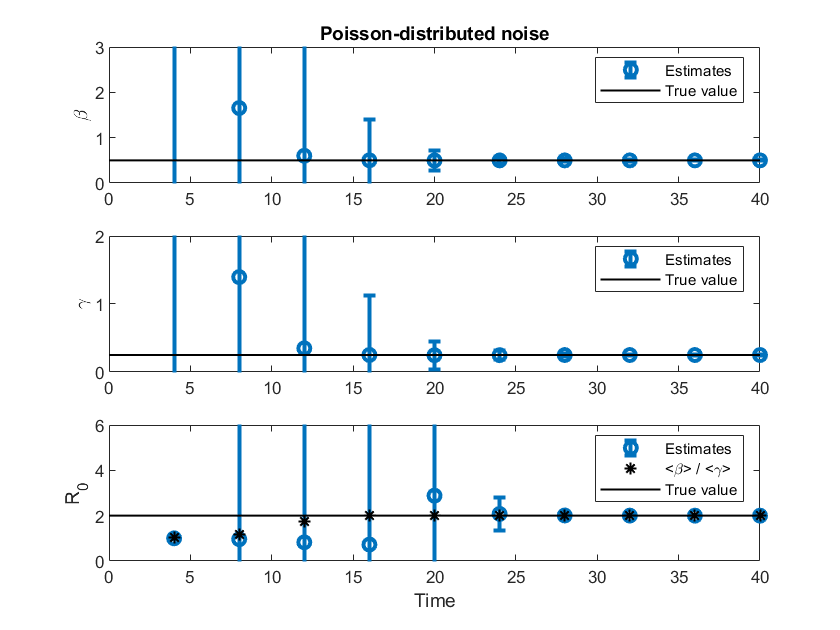

figure()
subplot(3,1,1)
errorbar(T1(M),mean(bet1,1),std(bet1,0,1),'o','LineWidth',2); hold on;
plot([0 T1(M(end))],[beta beta],'k-','LineWidth',1); hold off;
ylabel('\beta'); ylim([0 3]); legend('Estimates','True value')
title('Poisson-distributed noise')
subplot(3,1,2)
errorbar(T1(M),mean(gam1,1),std(gam1,0,1),'o','LineWidth',2); hold on;
plot([0 T1(M(end))],[beta/r01 beta/r01],'k-','LineWidth',1); hold off;
ylabel('\gamma'); ylim([0 2]); legend('Estimates','True value')
subplot(3,1,3)
errorbar(T1(M),mean(bet1./gam1,1),std(bet1./gam1,0,1),'o','LineWidth',2);
hold on;
plot(T1(M),mean(bet1,1)./mean(gam1,1),'k*',[0 T1(M(end))],[r01 r01],'k-',...
    'LineWidth',1);
hold off; legend('Estimates','<\beta> / <\gamma>','True value')
ylabel('R_0'); ylim([0 6]); xlabel('Time')

## Figures S2 & 6B

$R_0 = 2$** with  with normally-distributed multiplicatiove noise with 15% standard deviation**

rng default % For reproducibility
new_run=0;
if new_run==1
    DC1_ref=DC1(T1<=40); DIn1_ref=DIn1(T1<=40);
    DIn1_pert=zeros(N_run,length(DIn1_ref)); noise_size=0.15;  
    for j=1:N_run
        % Noisy incidence
        DIn1_pert(j,:)=DIn1_ref.*(1+noise_size*(randn(size(DIn1_ref))-0.5));
        DIn1_pert(1)=DIn1_ref(1);
        % Enforce same total number of cases at the end of the outbreak
        DIn1_pert(j,:)=DIn1_pert(j,:)*DC1_ref(end)/sum(DIn1_pert(j,:));
    end
    M=5:4:length(DC1_ref); bet1=zeros(size(DIn1_pert,1),length(M));
    gam1=bet1;
    for j=1:size(bet1,1)
        for k=1:length(M)
            DInN=DIn1_pert(j,1:M(k));
            DICCN=cumsum(DInN);
            C=(DICCN(2:end)+DICCN(1:end-1))/2; I=DInN(2:end)/dt1;
            [bet1(j,k),gam1(j,k),~,~]=find_beta_gamma_z(C,I,N);
        end
    end
    save(['./Data_files/SIR_' num2str(r01) '_realizations_Normal_' ...
        num2str(N_run) '.mat'],...
        'DC1_ref','DIn1_ref','DIn1_pert','T1','M','bet1','gam1');
else
    load(['./Data_files/SIR_' num2str(r01) '_realizations_Normal_' ...
        num2str(N_run) '.mat'],'T1','M','bet1','gam1');
end

The plots below show the distributions of $\beta_m,$ $\gamma_m,$ and $R_{0m} = \frac{\beta_m}{\gamma_m}$ at different time points.

**Temporal dependence of **$\beta_m$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges=[-100 -60:4:60 100];
histogram(bet1(:,1),edges,'Normalization','pdf'); hold on;
histogram(bet1(:,2),edges,'Normalization','pdf');
histogram(bet1(:,3),edges,'Normalization','pdf'); hold off;
xlabel('\beta_c'); xlim([-60 60]); ylabel('Density');
disp(['< beta_c > = [' num2str([mean(bet1(:,1)) mean(bet1(:,2)) ...
    mean(bet1(:,3))]) ']']);

< beta_c > = [3.8082      1.0174     0.62316]


legend(['T_m = ' num2str(T1(M(1)))],['T_m = ' num2str(T1(M(2)))],...
    ['T_m = ' num2str(T1(M(3)))],'Location','northwest')
subplot(1,3,2); edges = [-10 -4:9/30:5 10];
histogram(bet1(:,4),edges,'Normalization','pdf'); hold on;
histogram(bet1(:,5),edges,'Normalization','pdf');
histogram(bet1(:,6),edges,'Normalization','pdf'); hold off; xlim([-4 5]);
xlabel('\beta_c');
disp(['< beta_c > = [' num2str([mean(bet1(:,4)) mean(bet1(:,5)) ...
    mean(bet1(:,6))]) ']']);

< beta_c > = [0.53267      0.5045     0.50105]


legend(['T_m = ' num2str(T1(M(4)))],['T_m = ' num2str(T1(M(5)))],...
    ['T_m = ' num2str(T1(M(6)))],'Location','northeast')
subplot(1,3,3); edges = [-10 0:1/30:1 10];
histogram(bet1(:,7),edges,'Normalization','pdf'); hold on;
histogram(bet1(:,8),edges,'Normalization','pdf');
histogram(bet1(:,9),edges,'Normalization','pdf'); hold off; xlim([0 1]);
xlabel('\beta_c');
disp(['< beta_c > = [' num2str([mean(bet1(:,7)) mean(bet1(:,8)) ...
    mean(bet1(:,9))]) ']']);

< beta_c > = [0.50071     0.50052      0.5003]


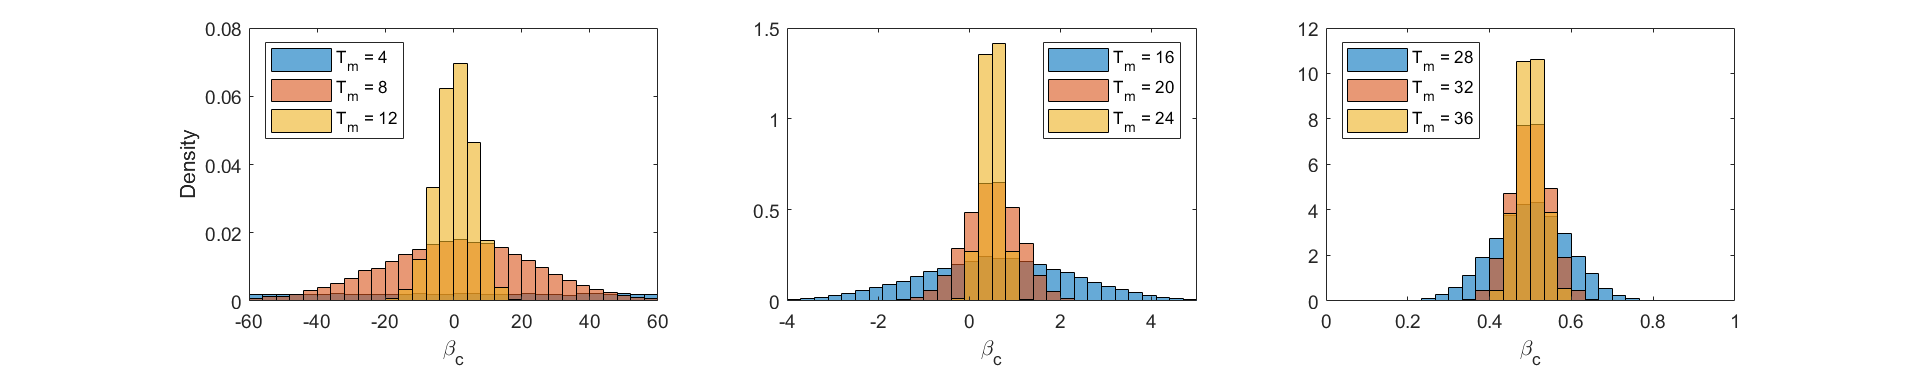

legend(['T_m = ' num2str(T1(M(7)))],['T_m = ' num2str(T1(M(8)))],...
    ['T_m = ' num2str(T1(M(9)))],'Location','northwest')

**Temporal dependence of **$\gamma_m$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges =[-100 -60:4:60 100];
histogram(gam1(:,1),edges,'Normalization','pdf'); hold on;
histogram(gam1(:,2),edges,'Normalization','pdf');
histogram(gam1(:,3),edges,'Normalization','pdf'); hold off;
xlabel('\gamma_c'); xlim([-60 60]); ylabel('Density');
disp(['< gamma_c > = [' num2str([mean(gam1(:,1)) ...
    mean(gam1(:,2)) mean(gam1(:,3))]) ']']);

< gamma_c > = [3.548     0.76365     0.37114]


legend(['T_m = ' num2str(T1(M(1)))],['T_m = ' num2str(T1(M(2)))],...
    ['T_m = ' num2str(T1(M(3)))],'Location','northwest')
subplot(1,3,2); edges = [-10 -4:8/30:4 10];
histogram(gam1(:,4),edges,'Normalization','pdf'); hold on;
histogram(gam1(:,5),edges,'Normalization','pdf');
histogram(gam1(:,6),edges,'Normalization','pdf'); hold off;
xlim([-4 4]); xlabel('\gamma_c');
disp(['< gamma_c > = [' num2str([mean(gam1(:,4)) ...
    mean(gam1(:,5)) mean(gam1(:,6))]) ']']);

< gamma_c > = [0.28139     0.25401      0.2507]


legend(['T_m = ' num2str(T1(M(4)))],['T_m = ' num2str(T1(M(5)))],...
    ['T_m = ' num2str(T1(M(6)))],'Location','northwest')
subplot(1,3,3); edges = [-1 0:0.5/30:0.5 1];
histogram(gam1(:,7),edges,'Normalization','pdf'); hold on;
histogram(gam1(:,8),edges,'Normalization','pdf');
histogram(gam1(:,9),edges,'Normalization','pdf'); hold off;
xlim([0 0.5]); xlabel('\gamma_c')
disp(['< gamma_c > = [' num2str([mean(gam1(:,7)) ...
    mean(gam1(:,8)) mean(gam1(:,9))]) ']']);

< gamma_c > = [0.25042     0.25032     0.25019]


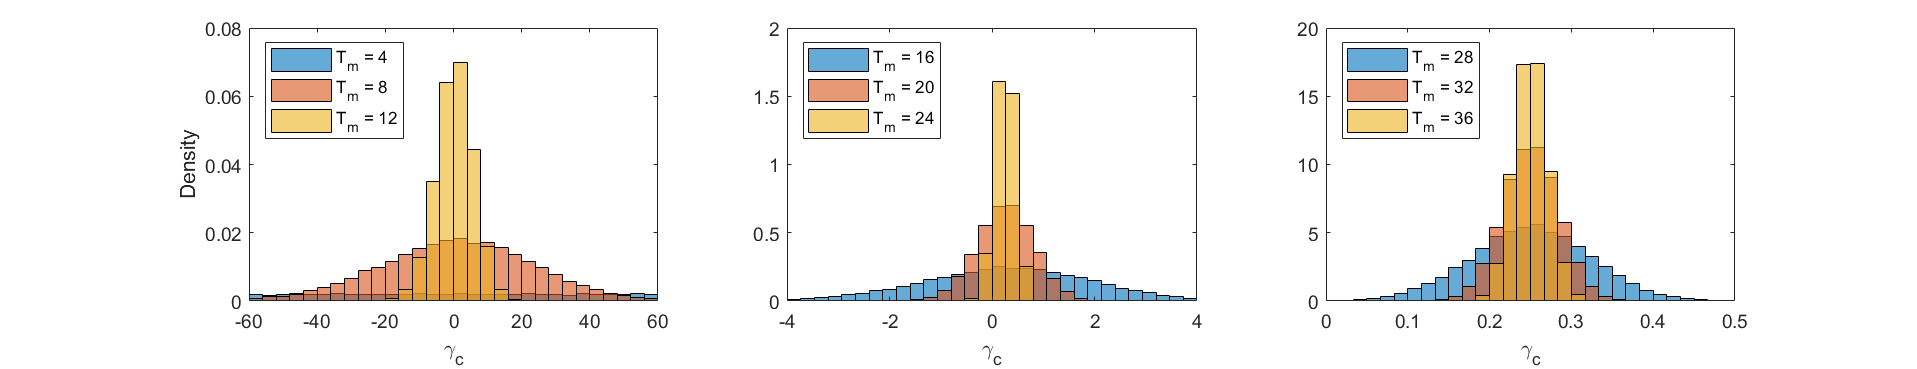

legend(['T_m = ' num2str(T1(M(7)))],['T_m = ' num2str(T1(M(8)))],...
    ['T_m = ' num2str(T1(M(9)))],'Location','northwest')

**Temporal dependence of **$R_0$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges = [-20 -3:6/30:3 20];
histogram(bet1(:,1)./gam1(:,1),edges,'Normalization','pdf'); hold on;
histogram(bet1(:,1)./gam1(:,2),edges,'Normalization','pdf');
histogram(bet1(:,3)./gam1(:,3),edges,'Normalization','pdf'); hold off;
xlim([-3 3]); xlabel('R_0'); ylabel('Density');
disp(['< R_0 > = [' num2str([mean(bet1(:,1)./gam1(:,1)) ...
    mean(bet1(:,2)./gam1(:,2)) mean(bet1(:,3)./gam1(:,3))]) ']']);

< R_0 > = [1.0012      1.0044      1.0207]


legend(['T_m = ' num2str(T1(M(1)))],['T_m = ' num2str(T1(M(2)))],...
    ['T_m = ' num2str(T1(M(3)))],'Location','northwest')
subplot(1,3,2); edges = [-10 -5:0.5:10 50];
histogram(bet1(:,4)./gam1(:,4),edges,'Normalization','pdf'); hold on;
histogram(bet1(:,5)./gam1(:,5),edges,'Normalization','pdf');
histogram(bet1(:,6)./gam1(:,6),edges,'Normalization','pdf');
hold off; xlim([-5 10]); xlabel('R_0');
disp(['< R_0 > = [' num2str([mean(bet1(:,4)./gam1(:,4)) ...
    mean(bet1(:,5)./gam1(:,5)) mean(bet1(:,6)./gam1(:,6))]) ']']);

< R_0 > = [1.7259      0.5731      2.5017]


legend(['T_m = ' num2str(T1(M(4)))],['T_m = ' num2str(T1(M(5)))],...
    ['T_m = ' num2str(T1(M(6)))],'Location','northeast')
subplot(1,3,3); edges = [-10 1.5:1.5/30:3 50];
histogram(bet1(:,7)./gam1(:,7),edges,'Normalization','pdf'); hold on;
histogram(bet1(:,8)./gam1(:,8),edges,'Normalization','pdf');
histogram(bet1(:,9)./gam1(:,9),edges,'Normalization','pdf'); hold off;
xlim([1.5 3]); xlabel('R_0');
disp(['< R_0 > = [' num2str([mean(bet1(:,7)./gam1(:,7)) ...
    mean(bet1(:,8)./gam1(:,8)) mean(bet1(:,9)./gam1(:,9))]) ']']);

< R_0 > = [2.0977      2.0117      2.0031]


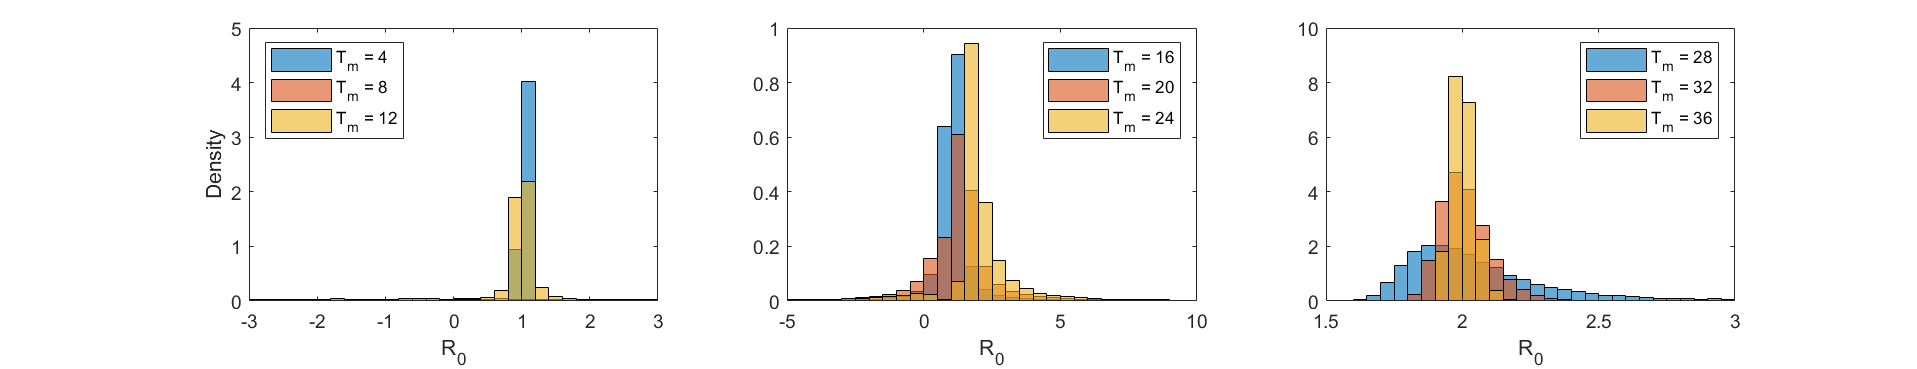

legend(['T_m = ' num2str(T1(M(7)))],['T_m = ' num2str(T1(M(8)))],...
    ['T_m = ' num2str(T1(M(9)))],'Location','northeast')

**Temporal evolution of estimated parameters**

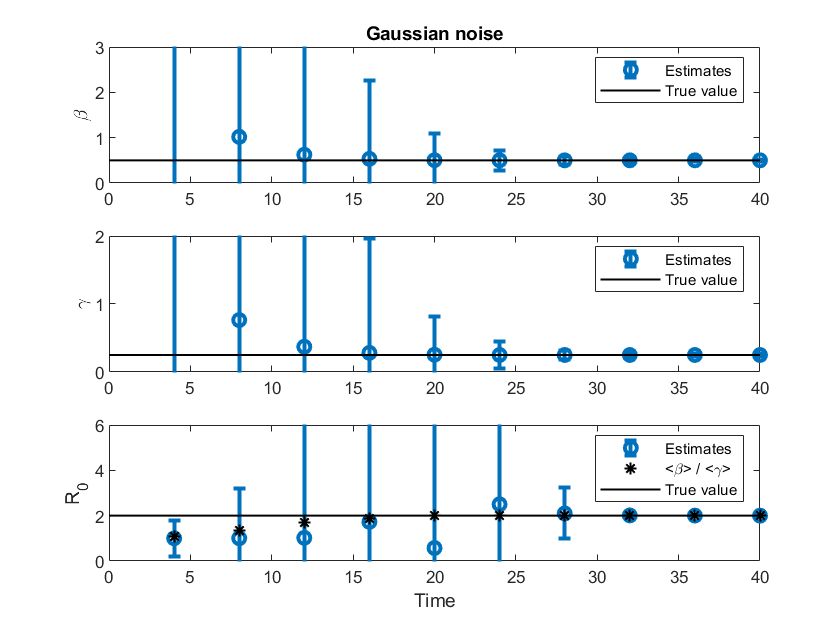

figure()
subplot(3,1,1)
errorbar(T1(M),mean(bet1,1),std(bet1,0,1),'o','LineWidth',2); hold on;
plot([0 T1(M(end))],[beta beta],'k-','LineWidth',1); hold off;
ylabel('\beta'); ylim([0 3]); legend('Estimates','True value')
title('Gaussian noise')
subplot(3,1,2)
errorbar(T1(M),mean(gam1,1),std(gam1,0,1),'o','LineWidth',2); hold on;
plot([0 T1(M(end))],[beta/r01 beta/r01],'k-','LineWidth',1); hold off;
ylabel('\gamma'); ylim([0 2]); legend('Estimates','True value')
subplot(3,1,3)
errorbar(T1(M),mean(bet1./gam1,1),std(bet1./gam1,0,1),'o','LineWidth',2);
hold on;
plot(T1(M),mean(bet1,1)./mean(gam1,1),'k*',[0 T1(M(end))],[r01 r01],'k-',...
    'LineWidth',1);
hold off; legend('Estimates','<\beta> / <\gamma>','True value')
ylabel('R_0'); ylim([0 6]); xlabel('Time')

## Figures S4 & S7A

$R_0 =10.5$** with Poisson-distributed noise**

rng default % For reproducibility
new_run=0;
if new_run==1
    DC2_ref=DC2(T2<=80); DIn2_ref=DIn2(T2<=80);
    DIn2_pert=zeros(N_run,length(DIn2_ref));
    for j=1:N_run
        % Noisy incidence
        DIn2_pert(j,:)=poissrnd(DIn2_ref);
        DIn2_pert(1)=DIn2_ref(1);
        % Enforce same total number of cases at the end of the outbreak
        DIn2_pert(j,:)=DIn2_pert(j,:)*DC2_ref(end)/sum(DIn2_pert(j,:));
    end
    M=4:2:length(DC2_ref); bet2=zeros(size(DIn2_pert,1),length(M));
    gam2=bet2;
    for j=1:size(bet2,1)
        for k=1:length(M)
            DInN=DIn2_pert(j,1:M(k));
            DICCN=cumsum(DInN);
            C=(DICCN(2:end)+DICCN(1:end-1))/2; I=DInN(2:end)/dt2;
            [bet2(j,k),gam2(j,k),~,~]=find_beta_gamma_z(C,I,N);
        end
    end
    save(['./Data_files/SIR_' num2str(r02) '_realizations_Poisson_' ...
        num2str(N_run) '.mat'],...
        'DC2_ref','DIn2_ref','DIn2_pert','T2','M','bet2','gam2');
else
    load(['./Data_files/SIR_' num2str(r02) '_realizations_Poisson_' ...
        num2str(N_run) '.mat'],'T2','M','bet2','gam2');
end

**Temporal dependence of **$\beta_m$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges=[-100 -30:2:30 100]; 
% Discard negative values of beta bb(bb<0)=[];
bb=bet2(:,1); m1=mean(bb);
histogram(bb,edges,'Normalization','pdf'); hold on;
bb=bet2(:,2); m2=mean(bb); histogram(bb,edges,'Normalization','pdf');
bb=bet2(:,3); m3=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold off; xlabel('\beta_c'); ylabel('Density');
disp(['< beta_c > = [' num2str([m1 m2 m3]) ']']); xlim([-30 30])

< beta_c > = [-0.42925     0.33273     0.40113]


legend(['T_m = ' num2str(T2(M(1)))],['T_m = ' num2str(T2(M(2)))],...
    ['T_m = ' num2str(T2(M(3)))])
subplot(1,3,2); edges = [-10 0.4:0.2/30:0.6 10];
bb=bet2(:,4); m1=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold on;
bb=bet2(:,5); m2=mean(bb); histogram(bb,edges,'Normalization','pdf');
bb=bet2(:,6); m3=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold off; xlabel('\beta_c');
disp(['< beta_c > = [' num2str([m1 m2 m3]) ']']);  xlim([0.4 0.6]);

< beta_c > = [0.48307     0.49402     0.49381]


legend(['T_m = ' num2str(T2(M(4)))],['T_m = ' num2str(T2(M(5)))],...
    ['T_m = ' num2str(T2(M(6)))])
subplot(1,3,3); edges = [-10 0.4:0.2/30:0.6 10];
bb=bet2(:,7); m1=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold on;
bb=bet2(:,8); m2=mean(bb); histogram(bb,edges,'Normalization','pdf');
bb=bet2(:,9); m3=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold off; xlabel('\beta_c');
disp(['< beta_c > = [' num2str([m1 m2 m3]) ']']);  xlim([0.4 0.6]);

< beta_c > = [0.4936     0.49354     0.49353]


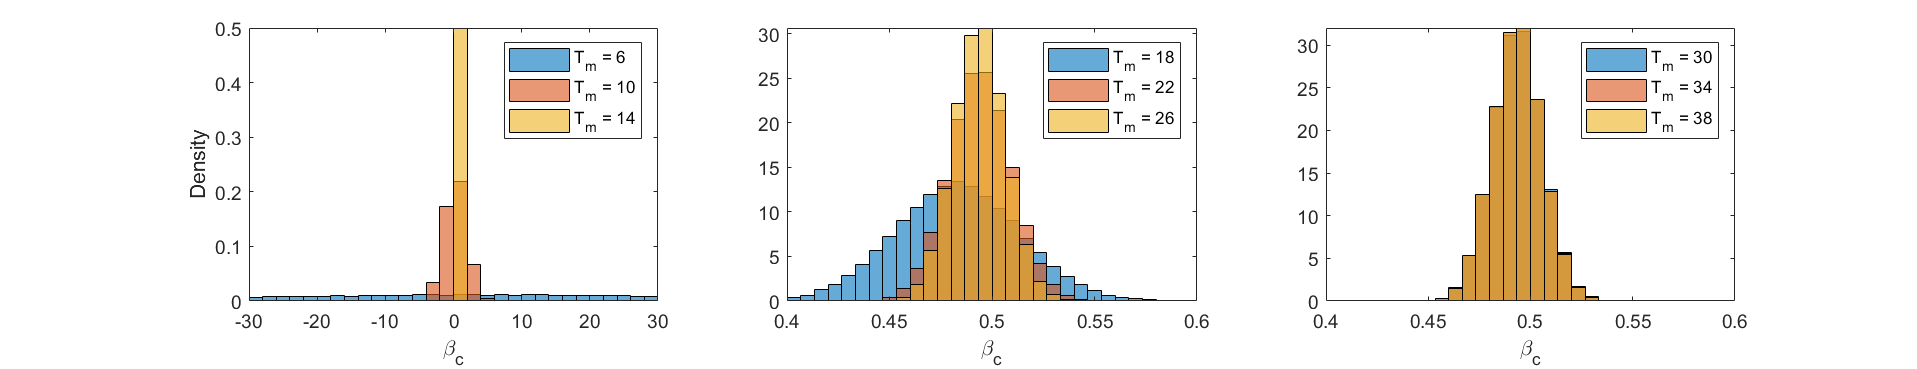

legend(['T_m = ' num2str(T2(M(7)))],['T_m = ' num2str(T2(M(8)))],...
    ['T_m = ' num2str(T2(M(9)))])

**Temporal dependence of **$\gamma_m$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges =[-100 -30:2:30 100];
% Discard negative values of gamma m2=mean(gg);
gg=gam2(:,1); m1=mean(gg);histogram(gg,edges,'Normalization','pdf');
hold on;
gg=gam2(:,2); m2=mean(gg); histogram(gg,edges,'Normalization','pdf');
gg=gam2(:,3); m3=mean(gg); histogram(gg,edges,'Normalization','pdf');
hold off;
xlabel('\gamma_c'); ylabel('Density');
disp(['< \gamma_c > = [' num2str([m1 m2 m3]) ']']); xlim([-30 30])

< \gamma_c > = [-0.84886   -0.091946   -0.027222]


legend(['T_m = ' num2str(T2(M(1)))],['T_m = ' num2str(T2(M(2)))],...
    ['T_m = ' num2str(T2(M(3)))])
subplot(1,3,2); edges = [-3 0:0.1/30:0.1 3];
gg=gam2(:,4); m1=mean(gg); histogram(gg,edges,'Normalization','pdf');
hold on;
gg=gam2(:,5); m2=mean(gg);histogram(gg,edges,'Normalization','pdf');
gg=gam2(:,6); m3=mean(gg);histogram(gg,edges,'Normalization','pdf');
hold off;
xlabel('\gamma_c'); disp(['< \gamma_c > = [' num2str([m1 m2 m3]) ']']);

< \gamma_c > = [0.041785    0.049804    0.049666]


xlim([0 0.1])
legend(['T_m = ' num2str(T2(M(4)))],['T_m = ' num2str(T2(M(5)))],...
    ['T_m = ' num2str(T2(M(6)))])
subplot(1,3,3); edges =  [-1 0:0.1/30:0.1 1];
gg=gam2(:,7); m1=mean(gg); histogram(gg,edges,'Normalization','pdf');
hold on;
gg=gam2(:,8); m2=mean(gg);histogram(gg,edges,'Normalization','pdf');
gg=gam2(:,9); m3=mean(gg);histogram(gg,edges,'Normalization','pdf');
hold off;
xlabel('\gamma_c'); disp(['< \gamma_c > = [' num2str([m1 m2 m3]) ']']);

< \gamma_c > = [0.049527    0.049492    0.049483]


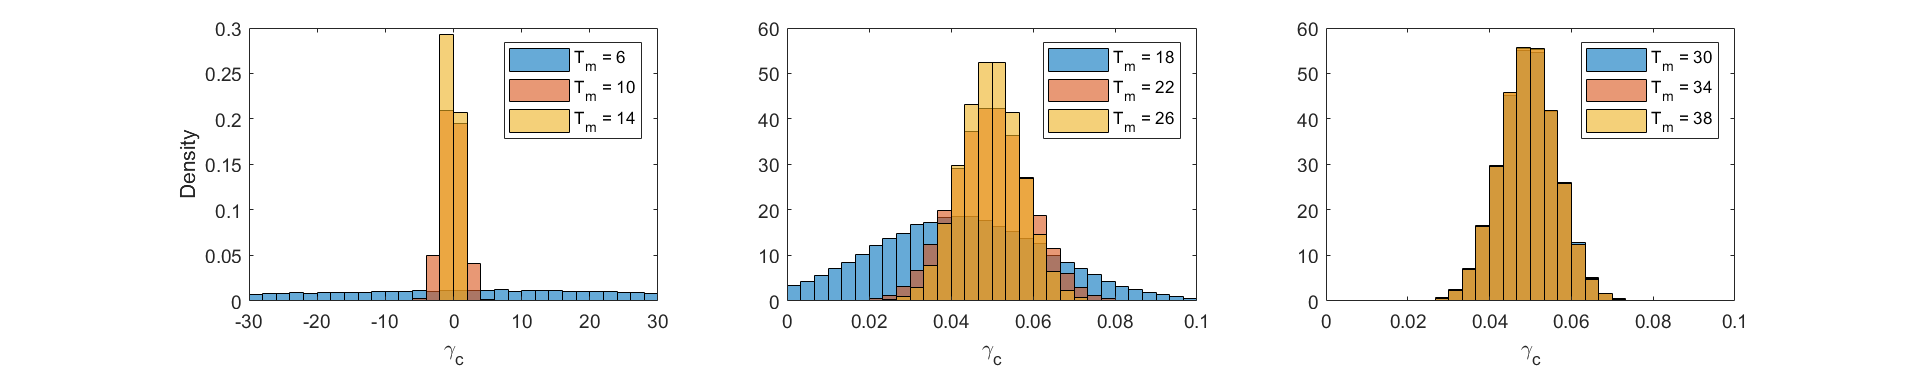

xlim([0 0.1]);
legend(['T_m = ' num2str(T2(M(7)))],['T_m = ' num2str(T2(M(8)))],...
    ['T_m = ' num2str(T2(M(9)))])

**Temporal dependence of **$R_0$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges =[-100 -20:2:40 100];
% Discard negative values of beta or gamma rr(rr<0|bet2(:,1)<0)=[]; 
rr=bet2(:,1)./gam2(:,1); m1=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold on;
rr=bet2(:,2)./gam2(:,2); m2=mean(rr); histogram(rr,edges,...
    'Normalization','pdf');
rr=bet2(:,3)./gam2(:,3); m3=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold off; 
xlabel('R_0'); xlim([-20 40]); ylabel('Density');
disp(['< R_{0} > = [' num2str([m1 m2 m3]) ']']); 

< R_{0} > = [0.77576      1.7104      6.0547]


legend(['T_m = ' num2str(T2(M(1)))],['T_m = ' num2str(T2(M(2)))],...
    ['T_m = ' num2str(T2(M(3)))])
subplot(1,3,2); edges = [-10 5:15/30:20 50];
rr=bet2(:,4)./gam2(:,4); m1=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold on;
rr=bet2(:,5)./gam2(:,5); m2=mean(rr); histogram(rr,edges,...
    'Normalization','pdf');
rr=bet2(:,6)./gam2(:,6); m3=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold off;
xlabel('R_0');  xlim([5 20]);
disp(['< R_{0} > = [' num2str([m1 m2 m3]) ']']);

< R_{0} > = [9.18207      10.2502      10.1438]


legend(['T_m = ' num2str(T2(M(4)))],['T_m = ' num2str(T2(M(5)))],...
    ['T_m = ' num2str(T2(M(6)))])
subplot(1,3,3); edges = [-10 5:15/30:20 50];
rr=bet2(:,7)./gam2(:,7); m1=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold on;
rr=bet2(:,8)./gam2(:,8); m2=mean(rr); histogram(rr,edges,...
    'Normalization','pdf');
rr=bet2(:,9)./gam2(:,9); m3=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold off;
xlabel('R_0'); xlim([5 20]);
disp(['< R_{0} > = [' num2str([m1 m2 m3]) ']']);

< R_{0} > = [10.1477      10.1495      10.1497]


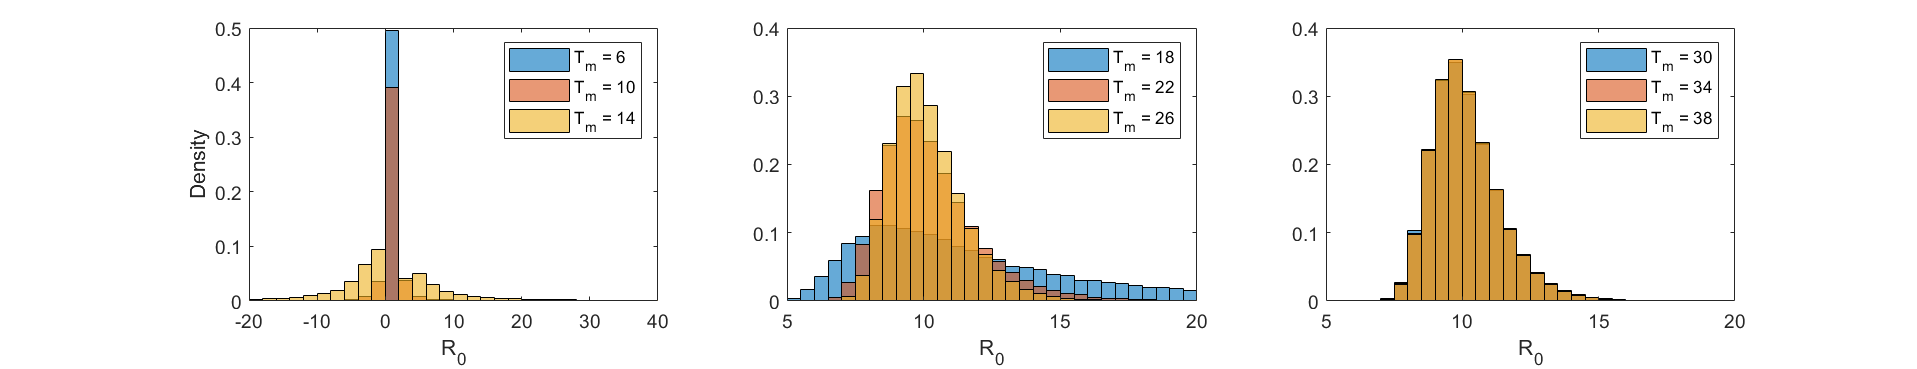

legend(['T_m = ' num2str(T2(M(7)))],['T_m = ' num2str(T2(M(8)))],...
    ['T_m = ' num2str(T2(M(9)))])

**Temporal evolution of estimated parameters**

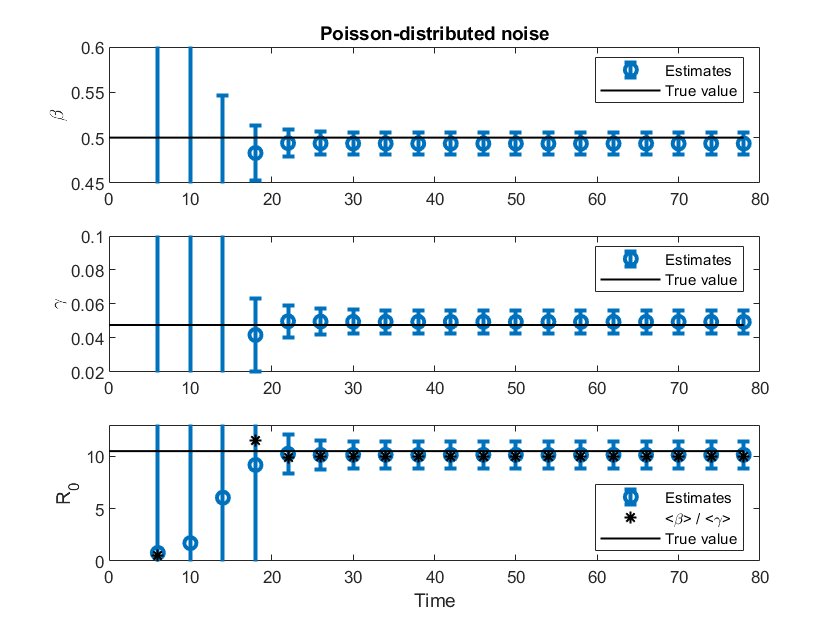

figure()
subplot(3,1,1)
errorbar(T2(M),mean(bet2,1),std(bet2,0,1),'o','LineWidth',2); hold on;
plot([0 T2(M(end))],[beta beta],'k-','LineWidth',1); hold off;
ylabel('\beta'); ylim([0.45 0.6]); legend('Estimates','True value')
title('Poisson-distributed noise')
subplot(3,1,2)
errorbar(T2(M),mean(gam2,1),std(gam2,0,1),'o','LineWidth',2); hold on;
plot([0 T2(M(end))],[beta/r02 beta/r02],'k-','LineWidth',1); hold off;
ylabel('\gamma'); ylim([0.02 0.1]); legend('Estimates','True value')
subplot(3,1,3)
errorbar(T2(M),mean(bet2./gam2,1),std(bet2./gam2,0,1),'o','LineWidth',2);
hold on;
plot(T2(M),mean(bet2,1)./mean(gam2,1),'k*',[0 T2(M(end))],[r02 r02],...
    'k-','LineWidth',1);
hold off;
legend('Estimates','<\beta> / <\gamma>','True value','Location',...
    'southeast')
ylabel('R_0'); ylim([0 13]); xlabel('Time')

## Figures S5 & S7B

$R_0 = 10.5,$** with normally-distributed multiplicatiove noise with 5% standard deviation**

rng default % For reproducibility
new_run=0; N_run=50000;
if new_run==1
    DC2_ref=DC2(T2<=80); DIn2_ref=DIn2(T2<=80);
    DIn2_pert=zeros(N_run,length(DIn2_ref)); noise_size=0.05;
    for j=1:N_run
        % Noisy incidence
        DIn2_pert(j,:)=DIn2_ref.*(1+noise_size*(randn(size(DIn2_ref))-0.5));
        DIn2_pert(1)=DIn2_ref(1);
        % Enforce same total number of cases at the end of the outbreak
        DIn2_pert(j,:)=DIn2_pert(j,:)*DC2_ref(end)/sum(DIn2_pert(j,:));
    end
    M=4:2:length(DC2_ref); bet2=zeros(size(DIn2_pert,1),length(M));
    gam2=bet2;
    for j=1:size(bet2,1)
        for k=1:length(M)
            DInN=DIn2_pert(j,1:M(k));
            DICCN=cumsum(DInN);
            C=(DICCN(2:end)+DICCN(1:end-1))/2; I=DInN(2:end)/dt2;
            [bet2(j,k),gam2(j,k),~,~]=find_beta_gamma_z(C,I,N);
        end
    end
    save(['./Data_files/SIR_' num2str(r02) '_realizations_Normal_05_' ...
        num2str(N_run) '.mat'],...
        'DC2_ref','DIn2_ref','DIn2_pert','T2','M','bet2','gam2');
else
%     load(['./Data_files/SIR_' num2str(r02) '_realizations_Normal_05_' ...
%         num2str(N_run) '.mat'],...
%         'DC2_ref','DIn2_ref','DIn2_pert','T2','M','bet2','gam2');
    load(['./Data_files/SIR_' num2str(r02) '_realizations_Normal_05_' ...
        num2str(N_run) '.mat'],'T2','M','bet2','gam2');
end

The plots below show the distributions of $\beta_m,$ $\gamma_m,$ and $R_{0m} = \frac{\beta_m}{\gamma_m}$ at different time points. In each case, we discard negative parameter values of $\beta_m$ or $\gamma_m.$

**Temporal dependence of **$\beta_m$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges=[-100 -30:2:30 100]; 
% Discard negative values of beta bb(bb<0)=[];
bb=bet2(:,1); m1=mean(bb);
histogram(bb,edges,'Normalization','pdf'); hold on;
bb=bet2(:,2); m2=mean(bb); histogram(bb,edges,'Normalization','pdf');
bb=bet2(:,3);m3=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold off; xlabel('\beta_c'); ylabel('Density');
disp(['< beta_c > = [' num2str([m1 m2 m3]) ']']); xlim([-30 30])

< beta_c > = [0.26231     0.34661     0.40356]


legend(['T_m = ' num2str(T2(M(1)))],['T_m = ' num2str(T2(M(2)))],...
    ['T_m = ' num2str(T2(M(3)))])
subplot(1,3,2); edges = [-10 0.2:0.6/30:0.8 10];
bb=bet2(:,4); m1=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold on;
bb=bet2(:,5); m2=mean(bb); histogram(bb,edges,'Normalization','pdf');
bb=bet2(:,6); m3=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold off; xlabel('\beta_c');
disp(['< beta_c > = [' num2str([m1 m2 m3]) ']']);  xlim([0.2 0.8]);

< beta_c > = [0.48286     0.49435     0.49418]


legend(['T_m = ' num2str(T2(M(4)))],['T_m = ' num2str(T2(M(5)))],...
    ['T_m = ' num2str(T2(M(6)))])
subplot(1,3,3); edges = [-10 0.2:0.6/30:0.8 10];
bb=bet2(:,7); m1=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold on;
bb=bet2(:,8); m2=mean(bb); histogram(bb,edges,'Normalization','pdf');
bb=bet2(:,9); m3=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold off; xlabel('\beta_c');
disp(['< beta_c > = [' num2str([m1 m2 m3]) ']']);  xlim([0.2 0.8]);

< beta_c > = [0.49397     0.49391     0.49389]


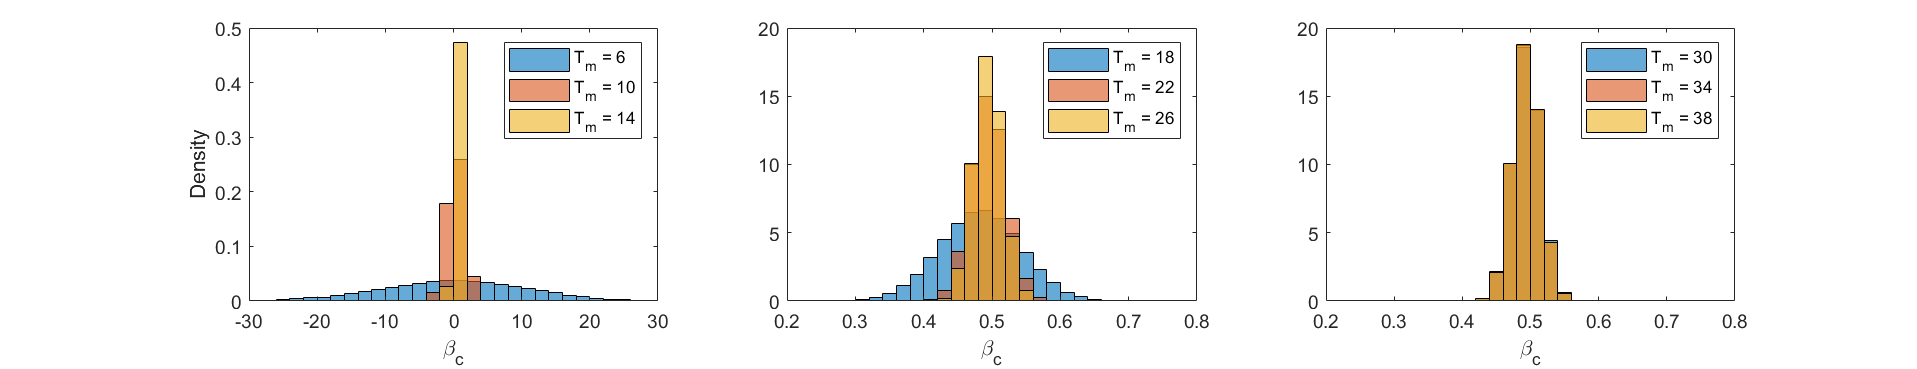

legend(['T_m = ' num2str(T2(M(7)))],['T_m = ' num2str(T2(M(8)))],...
    ['T_m = ' num2str(T2(M(9)))])

**Temporal dependence of **$\gamma_m$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges =[-100 -30:2:30 100];
% Discard negative values of gamma m2=mean(gg);
gg=gam2(:,1); m1=mean(gg);histogram(gg,edges,'Normalization','pdf');
hold on;
gg=gam2(:,2); m2=mean(gg); histogram(gg,edges,'Normalization','pdf');
gg=gam2(:,3); m3=mean(gg); histogram(gg,edges,'Normalization','pdf');
hold off;
xlabel('\gamma_c'); ylabel('Density');
disp(['< \gamma_m > = [' num2str([m1 m2 m3]) ']']); xlim([-30 30])

< \gamma_m > = [-0.16115   -0.078063   -0.025101]


legend(['T_m = ' num2str(T2(M(1)))],['T_m = ' num2str(T2(M(2)))],...
    ['T_m = ' num2str(T2(M(3)))])
subplot(1,3,2); edges = [-3 -0.1:0.3/30:0.2 3];
gg=gam2(:,4); m1=mean(gg); histogram(gg,edges,'Normalization','pdf');
hold on;
gg=gam2(:,5); m2=mean(gg);histogram(gg,edges,'Normalization','pdf');
gg=gam2(:,6); m3=mean(gg);histogram(gg,edges,'Normalization','pdf');
hold off;
xlabel('\gamma_c'); disp(['< \gamma_c > = [' num2str([m1 m2 m3]) ']']);

< \gamma_c > = [0.041449    0.049892    0.049786]


xlim([-0.1 0.2])
legend(['T_m = ' num2str(T2(M(4)))],['T_m = ' num2str(T2(M(5)))],...
    ['T_m = ' num2str(T2(M(6)))])
subplot(1,3,3); edges = [-3 -0.1:0.3/30:0.2 3];
gg=gam2(:,7); m1=mean(gg); histogram(gg,edges,'Normalization','pdf');
hold on;
gg=gam2(:,8); m2=mean(gg);histogram(gg,edges,'Normalization','pdf');
gg=gam2(:,9); m3=mean(gg);histogram(gg,edges,'Normalization','pdf');
hold off;
xlabel('\gamma_c'); disp(['< \gamma_c > = [' num2str([m1 m2 m3]) ']']);

< \gamma_c > = [0.049648    0.049608    0.049597]


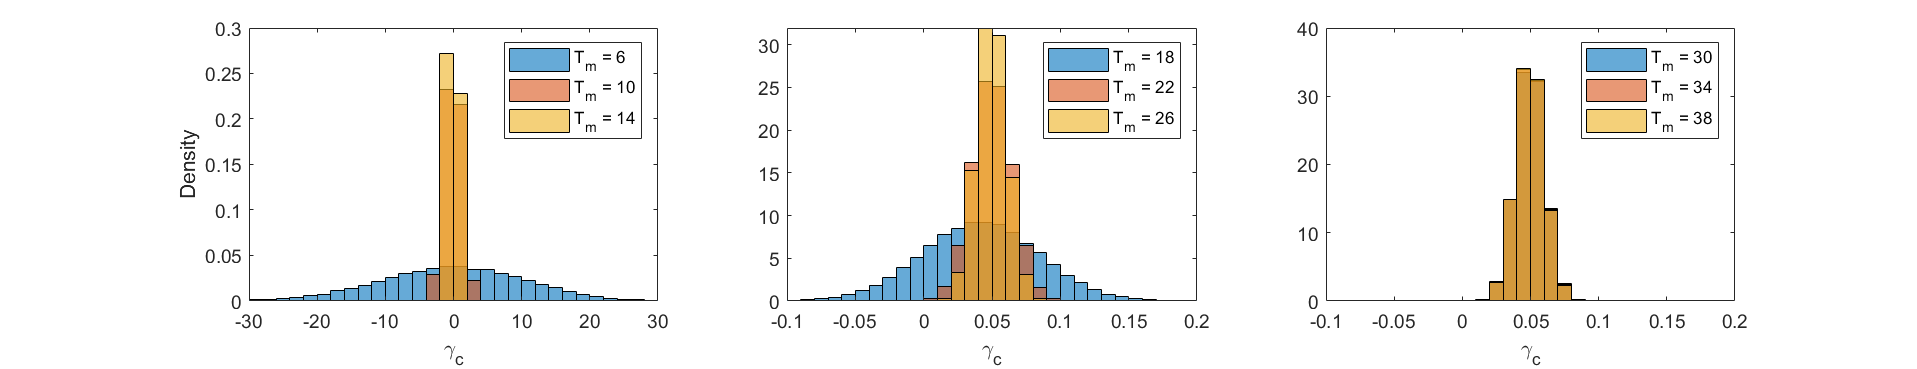

xlim([-0.1 0.2]);
legend(['T_m = ' num2str(T2(M(7)))],['T_m = ' num2str(T2(M(8)))],...
    ['T_m = ' num2str(T2(M(9)))])

**Temporal dependence of **$R_0$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges =[-100 -20:50/30:30 100];
% Discard negative values of beta or gamma rr(rr<0|bet2(:,1)<0)=[]; 
rr=bet2(:,1)./gam2(:,1); m1=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold on;
rr=bet2(:,2)./gam2(:,2); m2=mean(rr); histogram(rr,edges,...
    'Normalization','pdf');
rr=bet2(:,3)./gam2(:,3); m3=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold off; 
xlabel('R_0'); xlim([-20 30]); ylabel('Density');
disp(['< R_{0} > = [' num2str([m1 m2 m3]) ']']); 

< R_{0} > = [0.90306     0.99736      2.3658]


legend(['T_m = ' num2str(T2(M(1)))],['T_m = ' num2str(T2(M(2)))],...
    ['T_m = ' num2str(T2(M(3)))])
subplot(1,3,2); edges = [-10 0:40/30:40 50];
rr=bet2(:,4)./gam2(:,4); m1=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold on;
rr=bet2(:,5)./gam2(:,5); m2=mean(rr); histogram(rr,edges,...
    'Normalization','pdf');
rr=bet2(:,6)./gam2(:,6); m3=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold off;
xlabel('R_0');  xlim([0 40]);
disp(['< R_{0} > = [' num2str([m1 m2 m3]) ']']);

< R_{0} > = [-14.7202      10.8267      10.4132]


legend(['T_m = ' num2str(T2(M(4)))],['T_m = ' num2str(T2(M(5)))],...
    ['T_m = ' num2str(T2(M(6)))])
subplot(1,3,3); edges = [-10 0:40/30:40 50];
rr=bet2(:,7)./gam2(:,7); m1=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold on;
rr=bet2(:,8)./gam2(:,8); m2=mean(rr); histogram(rr,edges,...
    'Normalization','pdf');
rr=bet2(:,9)./gam2(:,9); m3=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold off;
xlabel('R_0'); xlim([0 40]);
disp(['< R_{0m} > = [' num2str([m1 m2 m3]) ']']);

< R_{0m} > = [10.3771      10.3721       10.371]


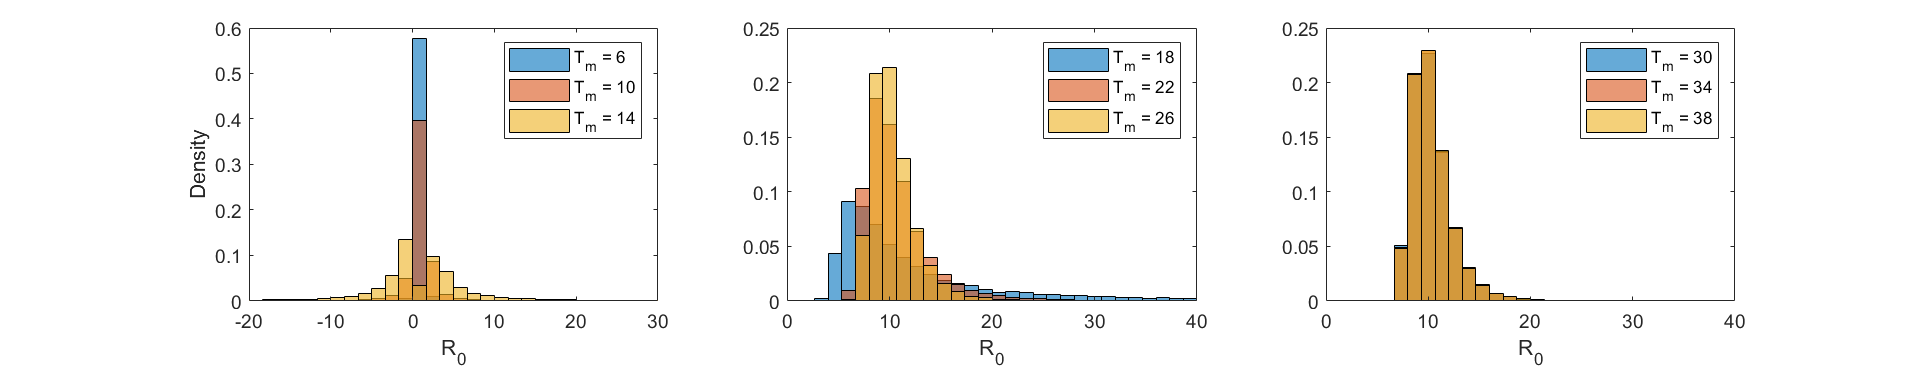

legend(['T_m = ' num2str(T2(M(7)))],['T_m = ' num2str(T2(M(8)))],...
    ['T_m = ' num2str(T2(M(9)))])

**Temporal evolution of estimated parameters**

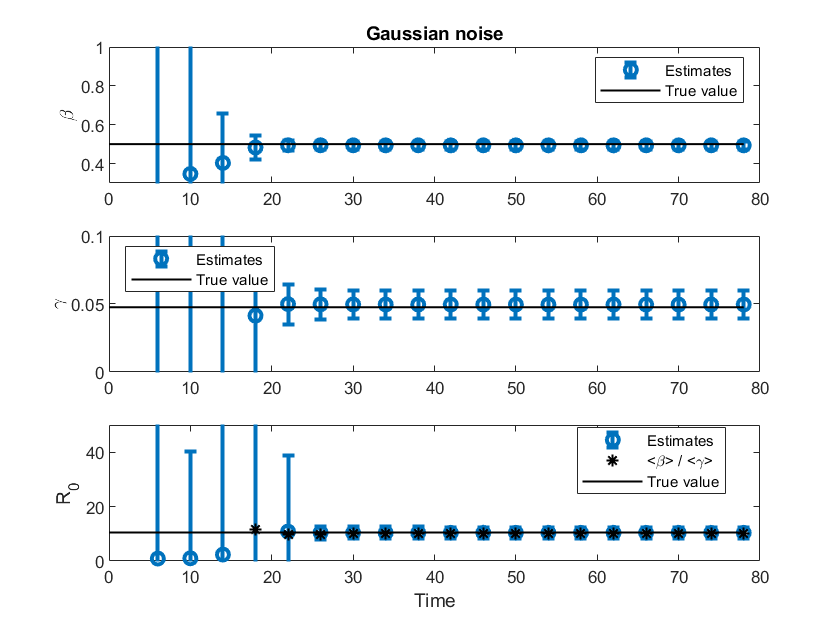

figure()
subplot(3,1,1)
errorbar(T2(M),mean(bet2,1),std(bet2,0,1),'o','LineWidth',2); hold on;
plot([0 T2(M(end))],[beta beta],'k-','LineWidth',1); hold off;
ylabel('\beta'); ylim([0.3 1]); legend('Estimates','True value')
title('Gaussian noise')
subplot(3,1,2)
errorbar(T2(M),mean(gam2,1),std(gam2,0,1),'o','LineWidth',2); hold on;
plot([0 T2(M(end))],[beta/r02 beta/r02],'k-','LineWidth',1); hold off;
ylabel('\gamma'); ylim([0 0.1]);
legend('Estimates','True value','Location','northwest')
subplot(3,1,3)
errorbar(T2(M),mean(bet2./gam2,1),std(bet2./gam2,0,1),'o','LineWidth',2);
hold on;
plot(T2(M),mean(bet2,1)./mean(gam2,1),'k*',[0 T2(M(end))],[r02 r02],...
    'k-','LineWidth',1);
hold off;
legend('Estimates','<\beta> / <\gamma>','True value','Location','best')
ylabel('R_0'); ylim([0 50]); xlabel('Time')

## Figures S6 & S8

$R_0 = 10.5,$** with normally-distributed multiplicatiove noise with 15% standard deviation**

rng default % For reproducibility
new_run=0;
if new_run==1
    DC2_ref=DC2(T2<=80); DIn2_ref=DIn2(T2<=80);
    DIn2_pert=zeros(N_run,length(DIn2_ref)); noise_size=0.15;
    for j=1:N_run
        % Noisy incidence
        DIn2_pert(j,:)=DIn2_ref.*(1+noise_size*(randn(size(DIn2_ref))-0.5));
        DIn2_pert(1)=DIn2_ref(1);
        % Enforce same total number of cases at the end of the outbreak
        DIn2_pert(j,:)=DIn2_pert(j,:)*DC2_ref(end)/sum(DIn2_pert(j,:));
    end
    M=4:2:length(DC2_ref); bet2=zeros(size(DIn2_pert,1),length(M));
    gam2=bet2;
    for j=1:size(bet2,1)
        for k=1:length(M)
            DInN=DIn2_pert(j,1:M(k));
            DICCN=cumsum(DInN);
            C=(DICCN(2:end)+DICCN(1:end-1))/2; I=DInN(2:end)/dt2;
            [bet2(j,k),gam2(j,k),~,~]=find_beta_gamma_z(C,I,N);
        end
    end
    save(['./Data_files/SIR_' num2str(r02) '_realizations_Normal_' ...
        num2str(N_run) '.mat'],...
        'DC2_ref','DIn2_ref','DIn2_pert','T2','M','bet2','gam2');
else
    load(['./Data_files/SIR_' num2str(r02) '_realizations_Normal_' ...
        num2str(N_run) '.mat'],...
        'T2','M','bet2','gam2');
end

The plots below show the distributions of $\beta_m,$ $\gamma_m,$ and $R_{0m} = \frac{\beta_m}{\gamma_m}$ at different time points. In each case, we discard negative parameter values of $\beta_m$ or $\gamma_m.$

**Temporal dependence of **$\beta_m$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges=[-100 -30:2:30 100]; 
% Discard negative values of beta bb(bb<0)=[];
bb=bet2(:,1); m1=mean(bb);
histogram(bb,edges,'Normalization','pdf'); hold on;
bb=bet2(:,2); m2=mean(bb); histogram(bb,edges,'Normalization','pdf');
bb=bet2(:,3);m3=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold off; xlabel('\beta_c'); ylabel('Density');
disp(['< beta_c > = [' num2str([m1 m2 m3]) ']']); xlim([-30 30])

< beta_c > = [-0.191     0.47859     0.42655]


legend(['T_m = ' num2str(T2(M(1)))],['T_m = ' num2str(T2(M(2)))],...
    ['T_m = ' num2str(T2(M(3)))])
subplot(1,3,2); edges = [-10 0.2:0.6/30:0.8 10];
bb=bet2(:,4); m1=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold on;
bb=bet2(:,5); m2=mean(bb); histogram(bb,edges,'Normalization','pdf');
bb=bet2(:,6); m3=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold off; xlabel('\beta_c');
disp(['< beta_c > = [' num2str([m1 m2 m3]) ']']);  xlim([0.2 0.8]);

< beta_c > = [0.48764     0.49836     0.49779]


legend(['T_m = ' num2str(T2(M(4)))],['T_m = ' num2str(T2(M(5)))],...
    ['T_m = ' num2str(T2(M(6)))])
subplot(1,3,3); edges = [-10 0.2:0.6/30:0.8 10];
bb=bet2(:,7); m1=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold on;
bb=bet2(:,8); m2=mean(bb); histogram(bb,edges,'Normalization','pdf');
bb=bet2(:,9); m3=mean(bb); histogram(bb,edges,'Normalization','pdf');
hold off; xlabel('\beta_c');
disp(['< beta_c > = [' num2str([m1 m2 m3]) ']']);  xlim([0.2 0.8]);

< beta_c > = [0.49752     0.49745     0.49743]


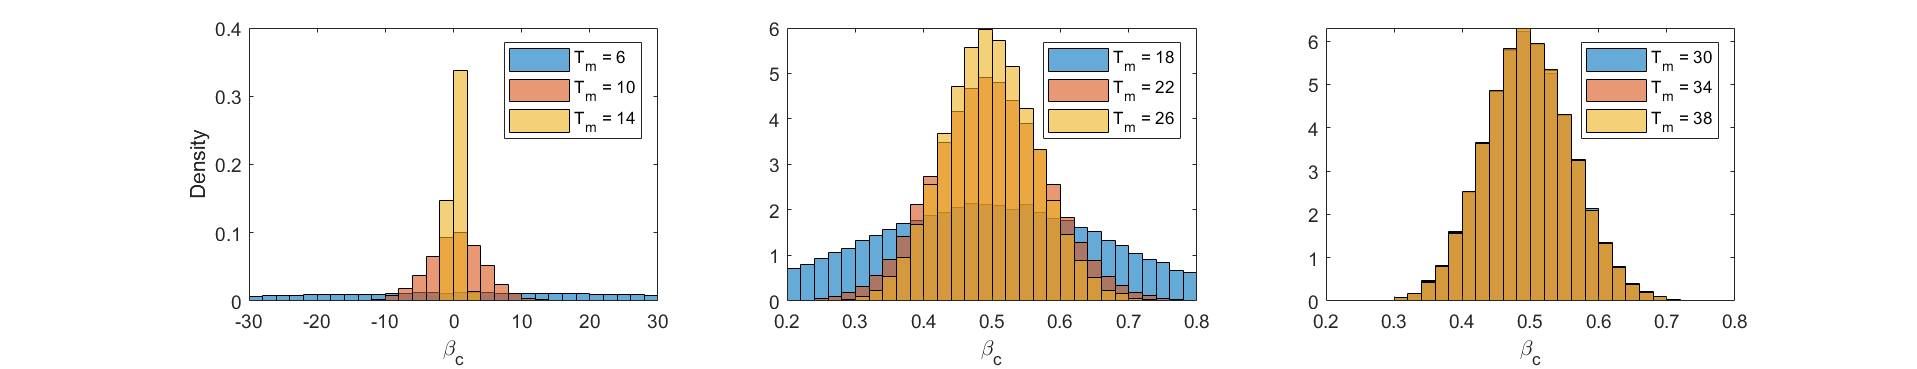

legend(['T_m = ' num2str(T2(M(7)))],['T_m = ' num2str(T2(M(8)))],...
    ['T_m = ' num2str(T2(M(9)))])

**Temporal dependence of **$\gamma_m$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges =[-100 -30:2:30 100];
% Discard negative values of gamma m2=mean(gg);
gg=gam2(:,1); m1=mean(gg);histogram(gg,edges,'Normalization','pdf');
hold on;
gg=gam2(:,2); m2=mean(gg); histogram(gg,edges,'Normalization','pdf');
gg=gam2(:,3); m3=mean(gg); histogram(gg,edges,'Normalization','pdf');
hold off;
xlabel('\gamma_c'); ylabel('Density');
disp(['< \gamma_c > = [' num2str([m1 m2 m3]) ']']); xlim([-30 30])

< \gamma_c > = [-0.61046    0.049439  -0.0067214]


legend(['T_m = ' num2str(T2(M(1)))],['T_m = ' num2str(T2(M(2)))],...
    ['T_m = ' num2str(T2(M(3)))])
subplot(1,3,2); edges = [-3 -0.1:0.3/30:0.2 3];
gg=gam2(:,4); m1=mean(gg); histogram(gg,edges,'Normalization','pdf');
hold on;
gg=gam2(:,5); m2=mean(gg);histogram(gg,edges,'Normalization','pdf');
gg=gam2(:,6); m3=mean(gg);histogram(gg,edges,'Normalization','pdf');
hold off;
xlabel('\gamma_c'); disp(['< \gamma_c > = [' num2str([m1 m2 m3]) ']']);

< \gamma_c > = [0.04296    0.051145    0.050845]


xlim([-0.1 0.2])
legend(['T_m = ' num2str(T2(M(4)))],['T_m = ' num2str(T2(M(5)))],...
    ['T_m = ' num2str(T2(M(6)))])
subplot(1,3,3); edges = [-3 -0.1:0.3/30:0.2 3];
gg=gam2(:,7); m1=mean(gg); histogram(gg,edges,'Normalization','pdf');
hold on;
gg=gam2(:,8); m2=mean(gg);histogram(gg,edges,'Normalization','pdf');
gg=gam2(:,9); m3=mean(gg);histogram(gg,edges,'Normalization','pdf');
hold off;
xlabel('\gamma_c'); disp(['< \gamma_c > = [' num2str([m1 m2 m3]) ']']);

< \gamma_c > = [0.050682    0.050638    0.050626]


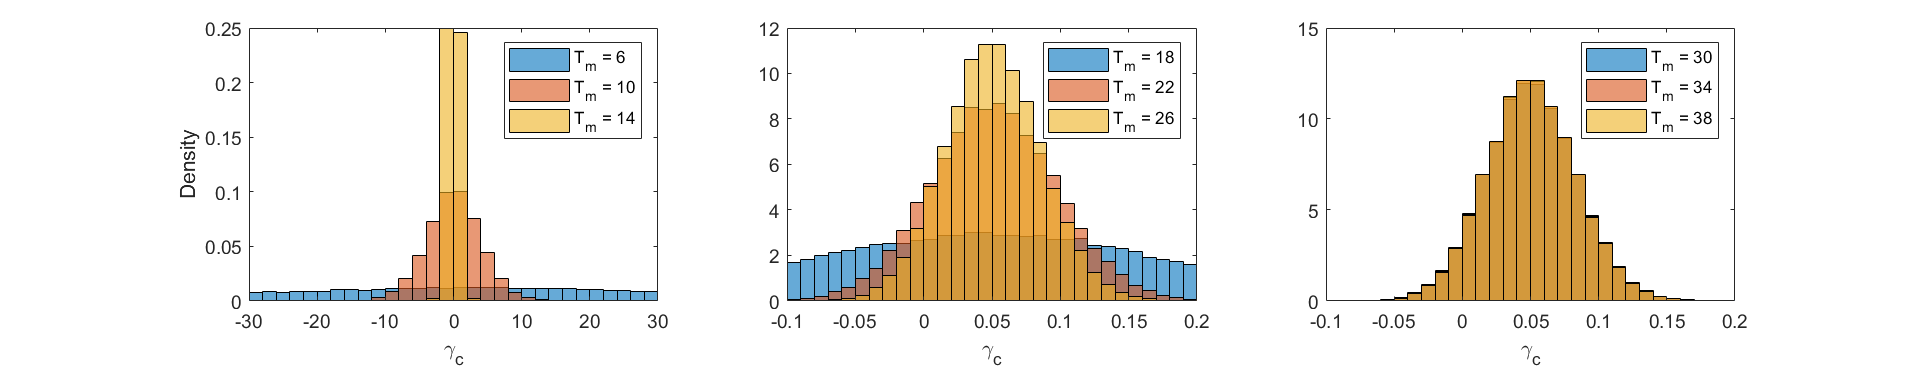

xlim([-0.1 0.2]);
legend(['T_m = ' num2str(T2(M(7)))],['T_m = ' num2str(T2(M(8)))],...
    ['T_m = ' num2str(T2(M(9)))])

**Temporal dependence of **$R_0$

figure(); set(gcf,'Position',[50 50 1300 250]);
subplot(1,3,1); edges =[-100 -20:50/30:30 100];
% Discard negative values of beta or gamma rr(rr<0|bet2(:,1)<0)=[]; 
rr=bet2(:,1)./gam2(:,1); m1=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold on;
rr=bet2(:,2)./gam2(:,2); m2=mean(rr); histogram(rr,edges,...
    'Normalization','pdf');
rr=bet2(:,3)./gam2(:,3); m3=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold off; 
xlabel('R_0'); xlim([-20 30]); ylabel('Density');
disp(['< R_{0} > = [' num2str([m1 m2 m3]) ']']); 

< R_{0} > = [1.0208      1.1805      2.6198]


legend(['T_m = ' num2str(T2(M(1)))],['T_m = ' num2str(T2(M(2)))],...
    ['T_m = ' num2str(T2(M(3)))])
subplot(1,3,2); edges = [-10 0:40/30:40 50];
rr=bet2(:,4)./gam2(:,4); m1=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold on;
rr=bet2(:,5)./gam2(:,5); m2=mean(rr); histogram(rr,edges,...
    'Normalization','pdf');
rr=bet2(:,6)./gam2(:,6); m3=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold off;
xlabel('R_0');  xlim([0 40]);
disp(['< R_{0} > = [' num2str([m1 m2 m3]) ']']);

< R_{0} > = [-45.4299      6.19543      1.45994]


legend(['T_m = ' num2str(T2(M(4)))],['T_m = ' num2str(T2(M(5)))],...
    ['T_m = ' num2str(T2(M(6)))])
subplot(1,3,3); edges = [-10 0:40/30:40 50];
rr=bet2(:,7)./gam2(:,7); m1=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold on;
rr=bet2(:,8)./gam2(:,8); m2=mean(rr); histogram(rr,edges,...
    'Normalization','pdf');
rr=bet2(:,9)./gam2(:,9); m3=mean(rr); histogram(rr,edges,...
    'Normalization','pdf'); hold off;
xlabel('R_0'); xlim([0 40]);
disp(['< R_{0} > = [' num2str([m1 m2 m3]) ']']);

< R_{0} > = [15.7171      16.0717      4.99193]


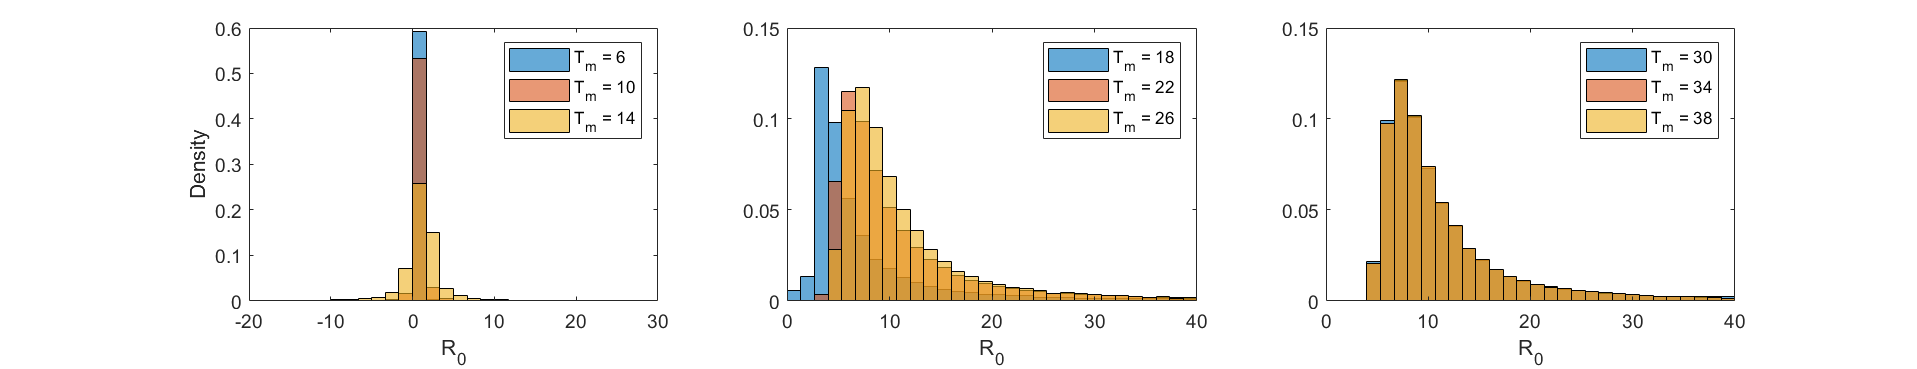

legend(['T_m = ' num2str(T2(M(7)))],['T_m = ' num2str(T2(M(8)))],...
    ['T_m = ' num2str(T2(M(9)))])

Interestingly, even very early in the course of the outbreak, $R_0$ is predicted to have a value larger than 1, indicating the epidemic will continue to spread. As the outbreak unfolds, with this type of noise, the mean of $R_0$ does not converge to its actual value due to the very long tails of the resulting distribution. The peak of the distribution however seems to stabilize near the correct value. As mentioned above, estimating $R_0$ from $<\beta_m>/<\gamma_m>$ provides a valid estimate. Note that these results are different from those with Poisson-distributed incidence, for which the mean of the $R_0$ distribution is close to its exact value about half-way through the course of the outbreak.

**Temporal evolution of estimated parameters**

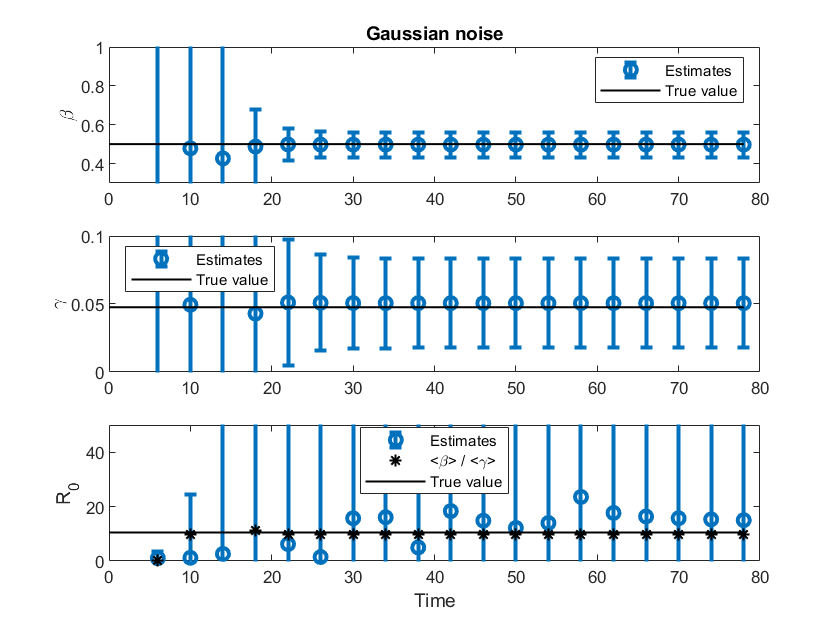

figure()
subplot(3,1,1)
errorbar(T2(M),mean(bet2,1),std(bet2,0,1),'o','LineWidth',2); hold on;
plot([0 T2(M(end))],[beta beta],'k-','LineWidth',1); hold off;
ylabel('\beta'); ylim([0.3 1]); legend('Estimates','True value')
title('Gaussian noise')
subplot(3,1,2)
errorbar(T2(M),mean(gam2,1),std(gam2,0,1),'o','LineWidth',2); hold on;
plot([0 T2(M(end))],[beta/r02 beta/r02],'k-','LineWidth',1); hold off;
ylabel('\gamma'); ylim([0 0.1]);
legend('Estimates','True value','Location','northwest')
subplot(3,1,3)
errorbar(T2(M),mean(bet2./gam2,1),std(bet2./gam2,0,1),'o','LineWidth',2);
hold on;
plot(T2(M),mean(bet2,1)./mean(gam2,1),'k*',[0 T2(M(end))],[r02 r02],...
    'k-','LineWidth',1);
hold off;
legend('Estimates','<\beta> / <\gamma>','True value','Location','best')
ylabel('R_0'); ylim([0 50]); xlabel('Time')

## Figures 7 & S9

The ICC curve is obtained by smoothing and interpolating the reported cumulative data. In particular, it estimates missing incidence values and interpolates between data points to remove negative incidence reports, if any. The resulting time series is considered to be a more realistic estimate of the "true" evolution of the cumulative data. 

clear variables;
% Read data file
location_name='Majorca'; pathname='./Data_files/';
fname='Gastro_Majorca_2008.xlsx';
filename=char(strcat(pathname,fname));
[A_raw,txt,~]=xlsread(filename); time_unit=txt(2,1);
T_cases=max(A_raw(:,3));
i_end_icc=size(A_raw,1); i_st_icc=1; t_max=A_raw(i_end_icc,1);
C_raw=A_raw(1:end,3); I_raw=[1; C_raw(2:end)-C_raw(1:end-1)];
% Smooth and interpolate the cumulative data - reduce the smoothing
% factor (the last argument of find_IC) to make estimates closer to data
smth_factor=6; [~,DC,~,C_ref]=...
    find_IC(C_raw(i_st_icc:i_end_icc),smth_factor);
DIn=DC; DIn(2:end)=DC(2:end)-DC(1:end-1); dt=A_raw(2,1)-A_raw(1,1);
C=(DC(2:end)+DC(1:end-1))/2; I=DIn(2:end)/dt; MI=max([max(I) max(I_raw)]);

Here, we use the formulas for $\beta$ and $\gamma$ established in the main document. If the observed data had been produced by a SIR model, these formulas would be the best estimates of the parameters $\beta$ and $\gamma$ of the model. Since we do not know the size of the susceptible population $N$ to be used in the SIR model, we run the model for a range of values of $N.$ Note that we have the freedom of not feeding the entire dataset to the model, but only the latest datapoints (for $i > i_{start}$).

% Calculate beta and gamma for different values of N
N_0 = C(end); nval=30000; RM=zeros(1,nval); bt=RM; gm=RM; ce=RM; z=RM;
i_start=1; nc=linspace(N_0+1,3*N_0,nval);     % Reange of values of N
% Note that find_beta_gamma_z uses points between i_start and length(C)
for j=1:nval
    [bt(j),gm(j),RM(j),z(j)]=...
        find_beta_gamma_z(C(i_start:end),I(i_start:end),nc(j));
    % Find final number of cases
    C_vals=linspace(0,1.5*nc(j),500);
    I_vals=ICC(0,C_vals,bt(j),gm(j),nc(j),nc(j)*(1-exp(z(j))));
    I_vals(I_vals<=0)=0; ik=find(I_vals(10:end)==0,1,'first')+9; 
    if isempty(ik)
        ik=length(C_vals);
    end
    ce(j)=C_vals(ik);    
end
% Optimal value of N
i_m=find(RM==min(RM)); N_m = nc(i_m);
X0=[sqrt(bt(i_m)),sqrt(gm(i_m)),nc(i_m),nc(i_m)*(1-exp(z(i_m)))];
f=@(X) find_err(X,I,C,4);
options = optimset('MaxFunEvals',50000,'MaxIter',20000);
X=fminsearch(f,X0,options);
C_vals=linspace(0,1.5*X(3),500);
I_opt=ICC(0,C_vals,X(1)^2,X(2)^2,X(3),X(4)); I_opt(I_opt<=0)=0;
i_opt_end=find(I_opt(10:end)==0,1,'first')+9;
C_opt_end=round(C_vals(i_opt_end));

We now find probability distributions for $\beta_m$ and $\gamma_m,$ using the bootstrapping method described in Chowell (2017). The idea is that a compartmental model describing the spread of the disease would, at each time point, report the mean incidence observed over many realizations of the same outbreak. It is therefore natural to model reported incidence as a random number drawn from a Poisson distribution of mean equal to the value predicted by the compartmental model we want to use, in the present case, the SIR model. Since we do not know this value, we use instead the incidence predicted by the ICC curve (`DIn`). 

We therefore create 10,000 realizations of the outbreak described by the smoothed and interpolated data, assuming 200 different values of $N$ in the range $[N_{min}, N_{max}].$ The code `find_param_Poisson.m` calculates the values of $\beta_m$, $\gamma_m$, and $z_m$ for each realization of the outbreak. 

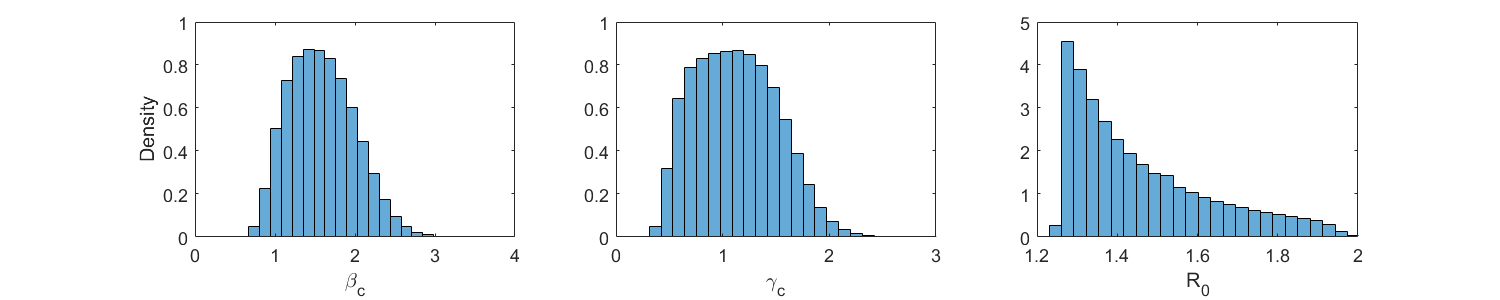

N_run=10000;
k=find(RM<=1.02*f(X) & nc>80);
kvals=unique([i_m, round(linspace(min(k),max(k),200))]);
Nvals=nc(kvals); new_run=0;
if new_run==1
    bet=zeros(length(kvals),N_run); gam=bet; zn=bet;
    for i=1:length(kvals)
        for j=1:N_run
            [bet(i,j),gam(i,j),~,~,zn(i,j)]=...
                find_param_Poisson(DC,DIn,dt,Nvals(i));
        end
    end
    save(['./Data_files/Gastro_Majorca_' location_name '_param_Poisson_' ...
        num2str(N_run) '.mat'],'Nvals','bet','gam','zn');
else
    load(['./Data_files/Gastro_Majorca_' location_name '_param_Poisson_' ...
        num2str(N_run) '.mat'],'Nvals','bet','gam','zn');
end
Ndata=size(bet,1)*size(bet,2); bet=reshape(bet,[1,Ndata]);
gam=reshape(gam,[1,Ndata]); r0=reshape(bet./gam,[1,Ndata]);
figure(); set(gcf,'Position',[50 50 1000 200]);
subplot(1,3,1); histogram(bet,30,'Normalization','pdf');
xlabel('\beta_c'); ylabel('Density'); xlim([0 4])
subplot(1,3,2); histogram(gam,30,'Normalization','pdf');
xlabel('\gamma_c'); xlim([0 3])
subplot(1,3,3);
histogram(r0,30,'Normalization','pdf');
xlabel('R_0'); xlim([1.2 2])

zc=zeros(size(Nvals));
for i=1:length(Nvals)
    zc(i)=mean(Nvals(i)*(1-exp(zn(i,:))));
end
be=mean(bet); ga=mean(gam); N=mean(Nvals); zz=mean(zc);
disp(['Average values: beta = ' num2str(be) ' - gamma = ' num2str(ga) ...
    ' - N = ' num2str(N) ' - C_0 = ' num2str(zz) ' - R_0 = ' ...
    num2str(mean(bet./gam))])

Average values: beta = 1.5857 - gamma = 1.1257 - N = 139.2104 - C_0 = -0.034748 - R_0 = 1.4596


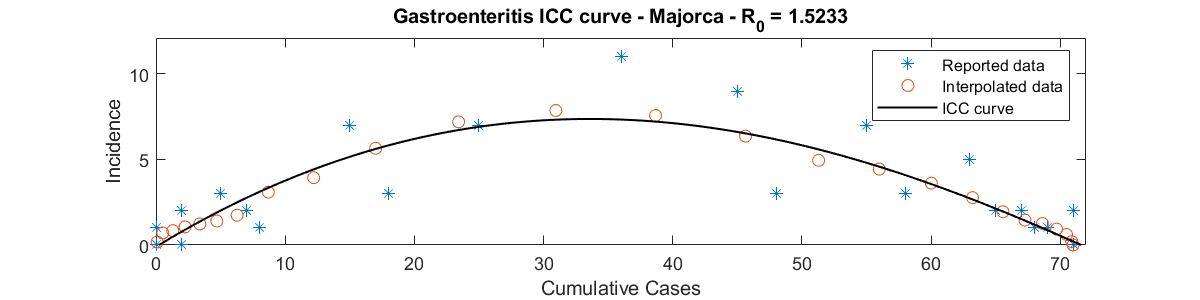

% Plot ICC curve with estimated parameter values
figure(); set(gcf,'Position',[50 50 800 200]);
plot(C_raw,I_raw,'*'); hold on; plot(C,I,'o');
sc=N/DC(end);
plot(C_ref*sc,ICC(0,C_ref*sc,X(1)^2,X(2)^2,X(3),X(4)),'k-','LineWidth',1);
hold off; xlim([0 C_opt_end]); ylim([0 1.1*MI]);
xlabel('Cumulative Cases'); ylabel('Incidence');
legend('Reported data','Interpolated data','ICC curve',...
    'Location','northeast')
title(['Gastroenteritis ICC curve - ' location_name ' - R_0 = ' ...
    num2str(X(1)^2/X(2)^2)]);

Finally, we integrate the ICC curve with the mean parameter values, and compare it to the reported data.  Alignment is sensitive to the value of i_align chosen.

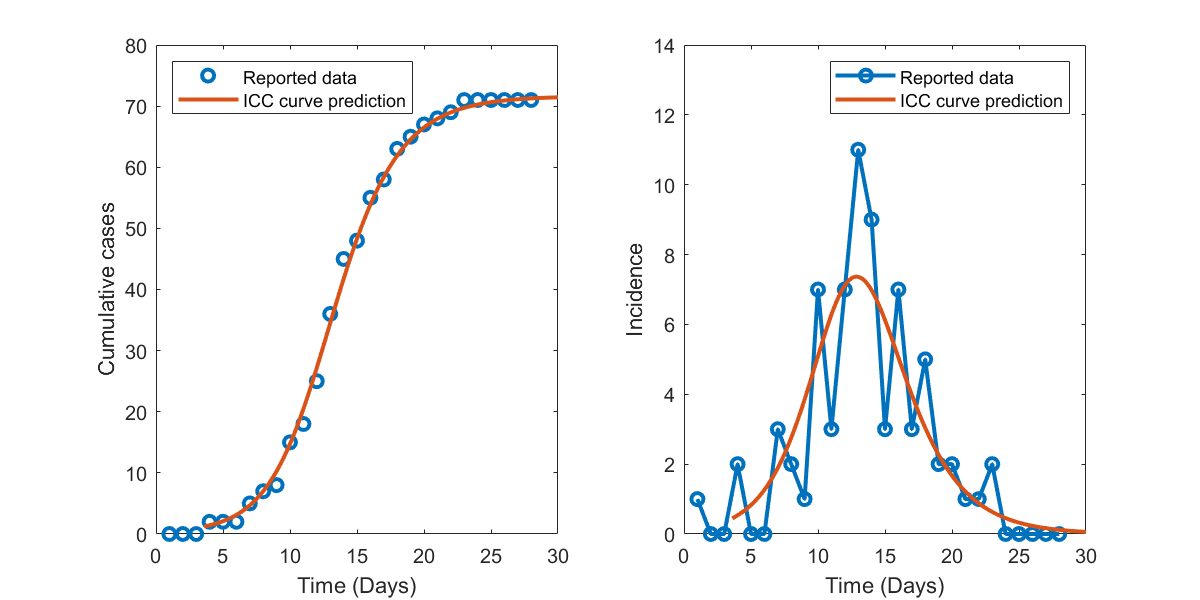

% ICC curve
icc=@(x) ICC(0,x,X(1)^2,X(2)^2,X(3),X(4)); tme=1:1:length(C);
% icc=@(x) ICC(0,x,be,ga,round(N),zz); tme=1:1:length(C);
% Parameters
i_start=5; i_align=10;
% Integrate ICC curve
[t,y] = ode45(@(t,y) icc(y), tme(i_start):0.1:round(length(I_raw)*1.2), ...
    mean(I(i_start-1:i_start+1)));
% Find integration constant by shifting time
t_sw=tme(i_align); %t_sw=tme(i_start+i_sw-1);
i_shft=find(y>C(i_align),1,'first'); t=t-t(i_shft)+t_sw+1/2;
figure(); set(gcf,'Position',[50 50 800 400]);
subplot(1,2,1)
plot(1:dt:length(I_raw),C_raw,'o',t,y,'-','LineWidth',2); xlim([0 30])
xlabel(['Time (' time_unit{1} 's)']); ylabel('Cumulative cases');
legend('Reported data','ICC curve prediction','Location','northwest')
subplot(1,2,2)
plot(1:dt:length(I_raw),I_raw,'o-',t,icc(y),'-','LineWidth',2); xlim([0 30])
xlabel(['Time (' time_unit{1} 's)']); ylabel('Incidence'); ylim([0 14])
legend('Reported data','ICC curve prediction','Location','northeast')

## Figures 8A & 9

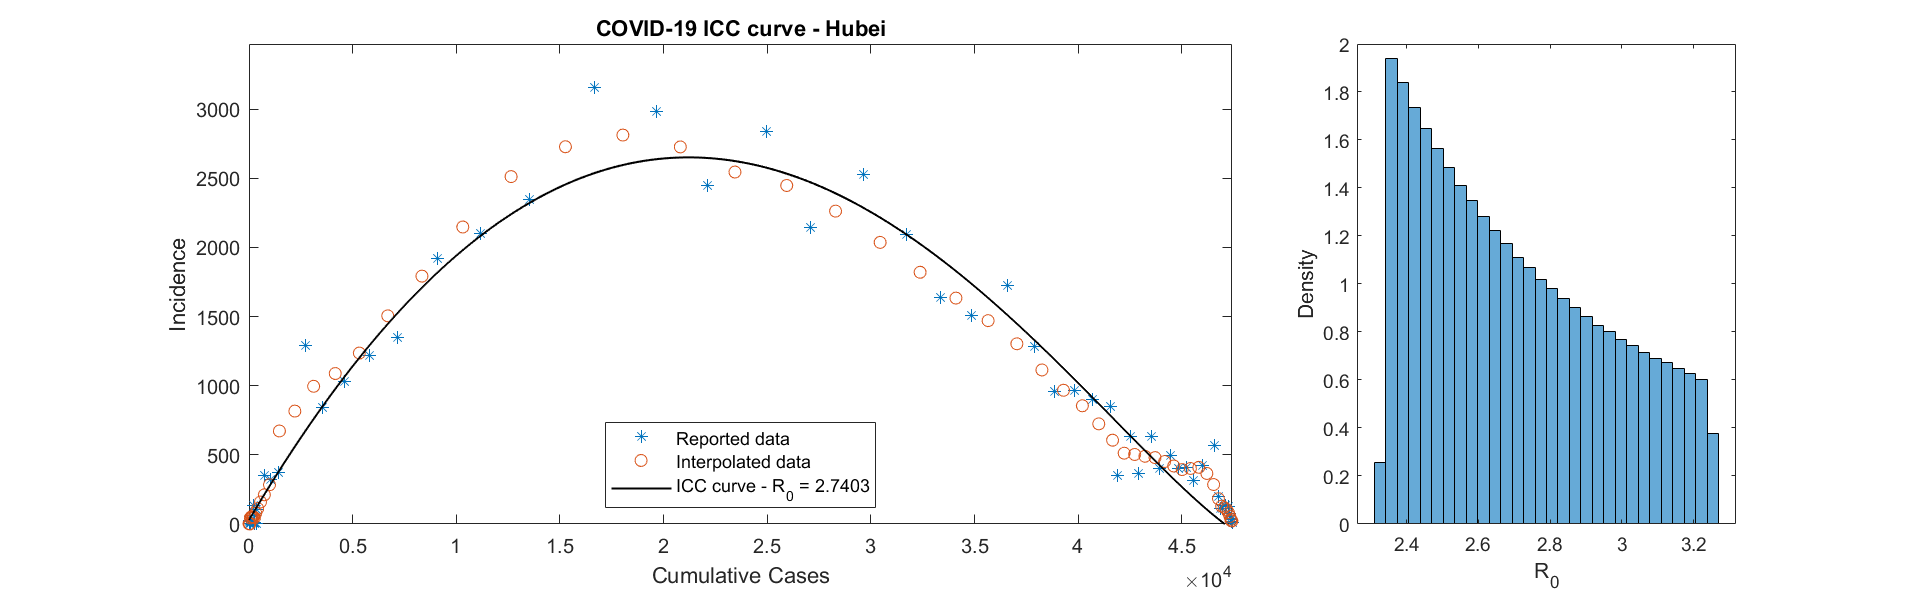

clear variables;
% Read data file
location_name='Hubei'; pathname='./Data_files/'; fname='Hubei.xlsx';
filename=char(strcat(pathname,fname));
[A_raw,txt,~]=xlsread(filename); time_unit=txt(2,1);
i_end_icc=size(A_raw,1); i_st_icc=1;
C_raw=A_raw(1:end,3); I_raw=[1; C_raw(2:end)-C_raw(1:end-1)];
% Smooth and interpolate the cumulative data - reduce the smoothing
% factor (the last argument of find_IC) to make estimates closer to data
smth_factor=6; [~,DC,~,C_ref]=...
    find_IC(C_raw(i_st_icc:i_end_icc),smth_factor);
DIn=DC; DIn(2:end)=DC(2:end)-DC(1:end-1); dt=A_raw(2,1)-A_raw(1,1);
C=(DC(2:end)+DC(1:end-1))/2; I=DIn(2:end)/dt; MI=max([max(I) max(I_raw)]);
% Calculate beta and gamma for different values of N
N_0 = C(end); nval=30000; RM=zeros(1,nval); bt=RM; gm=RM; z=RM;
nc=round(linspace(N_0+1,2*N_0,nval));     % Reange of values of N
% Note that find_beta_gamma_z uses points between i_start and length(C)
for j=1:nval
    [bt(j),gm(j),RM(j),z(j)]=find_beta_gamma_z(C,I,nc(j));
end
% Optimal value of N
i_m=find(RM==min(RM)); %N_m = nc(i_m);
X0=[sqrt(bt(i_m)),sqrt(gm(i_m)),nc(i_m),nc(i_m)*(1-exp(z(i_m)))];
f=@(X) find_err(X,I,C,4);
options = optimset('MaxFunEvals',50000,'MaxIter',20000);
X=fminsearch(f,X0,options);
% Parameter estimation
k=find(RM<=1.02*f(X)); n_min=min(nc(k)); n_max=max(nc(k));
%kvals=unique([i_m, round(linspace(min(k),max(k),10))]);
nc=n_min:1:n_max; bet=nc; gam=nc; zn=nc;
for j=1:length(nc)
    [bet(j),gam(j),~,zn(j)]=find_beta_gamma_z(C,I,nc(j));
end
N=mean(nc); sc=N/DC(end);
% Combined Figure showing the range of R_0 and the ICC curve
figure(); set(gcf,'Position',[0 0 1400 430]);
subplot(1,15,[1,10])
plot(C_raw,I_raw,'*'); hold on; plot(C,I,'o'); xlabel('Cumulative Cases'); 
plot(C_ref*sc,ICC(0,C_ref*sc,X(1)^2,X(2)^2,X(3),X(4)),'k-','LineWidth',1);
hold off; xlim([0 max(C_raw)]); ylim([0 1.1*MI]);
ylabel('Incidence'); title(['COVID-19 ICC curve - ' location_name ])
legend('Reported data','Interpolated data',...
    ['ICC curve - R_0 = ' num2str(X(1)^2/X(2)^2)],'Location','south')
subplot(1,15,[12,15])
histogram(bet./gam,30,'Normalization','pdf');
xlabel('R_0'); ylabel('Density');

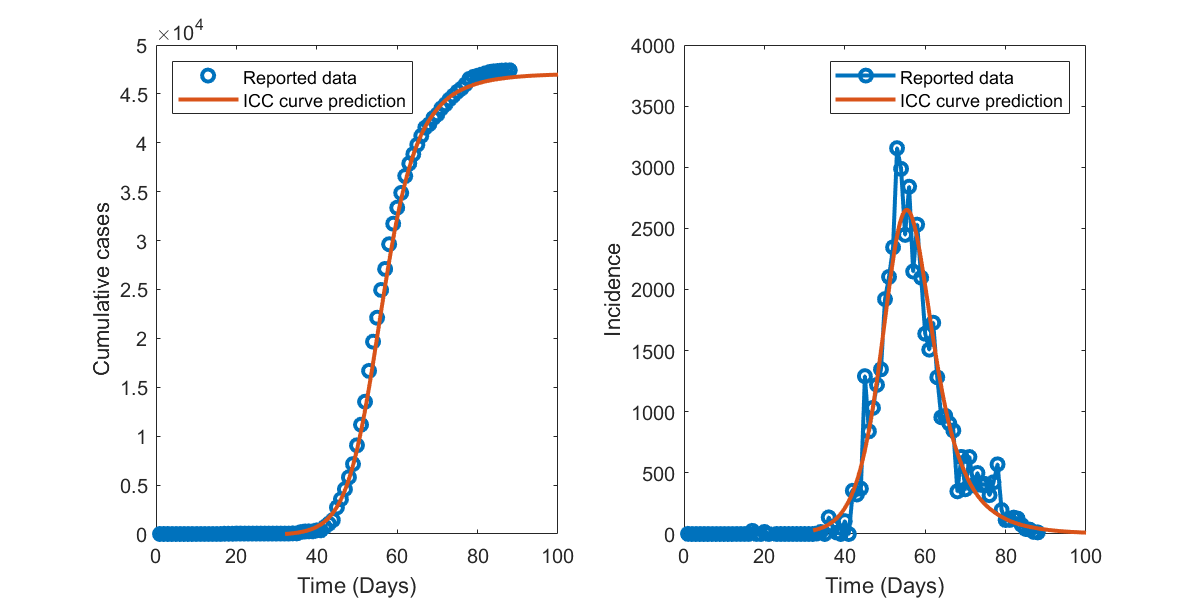

% ICC curve
icc=@(x) ICC(0,x,X(1)^2,X(2)^2,X(3),X(4)); tme=1:1:length(C);
% Parameters
i_start=10; i_align=min(45,length(tme));
% Integrate ICC curve
[t,y] = ode45(@(t,y) icc(y), tme(i_start):0.1:round(length(I_raw)*1.2), ...
    mean(I(i_start-1:i_start+1)));
% Find integration constant by shifting time
t_sw=tme(i_align);
i_shft=find(y>C(i_align),1,'first'); t=t-t(i_shft)+t_sw+1/2;
figure(); set(gcf,'Position',[50 50 800 400]);
subplot(1,2,1)
plot(1:dt:length(I_raw),C_raw,'o',t,y,'-','LineWidth',2); xlim([0 100])
xlabel(['Time (' time_unit{1} 's)']); ylabel('Cumulative cases');
legend('Reported data','ICC curve prediction','Location','northwest')
subplot(1,2,2)
plot(1:dt:length(I_raw),I_raw,'o-',t,icc(y),'-','LineWidth',2); xlim([0 100])
xlabel(['Time (' time_unit{1} 's)']); ylabel('Incidence'); ylim([0 4000])
legend('Reported data','ICC curve prediction','Location','northeast')

## Figures 8B & S10

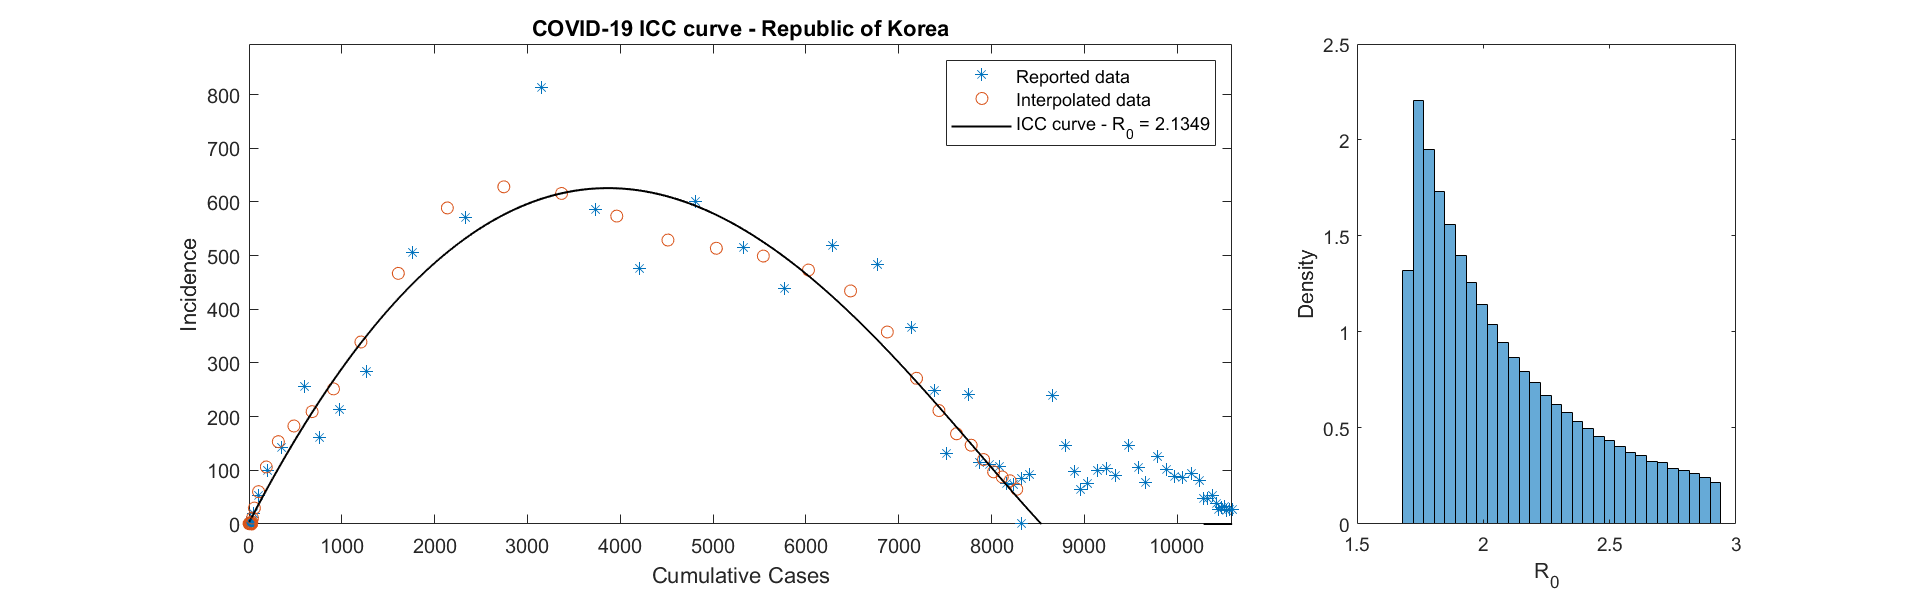

clear variables;
% Read data file
pathname='./Data_files/'; fname='Republic of Korea';
filename=char(strcat(pathname,[fname '.xlsx']));
[A_raw,txt,~]=xlsread(filename); time_unit=txt(2,1);
i_end_icc=size(A_raw,1); i_st_icc=1;
C_raw=A_raw(1:end,3); I_raw=[1; C_raw(2:end)-C_raw(1:end-1)];
% Smooth and interpolate the cumulative data - reduce the smoothing factor
% (the last argument of find_IC) to make estimates closer to data
smth_factor=6; [~,DC,~,C_ref]=find_IC(C_raw(i_st_icc:i_end_icc),...
    smth_factor);
DIn=DC; DIn(2:end)=DC(2:end)-DC(1:end-1); dt=A_raw(2,1)-A_raw(1,1);
DC=DC(1:58); DIn=DIn(1:58);
C=(DC(2:end)+DC(1:end-1))/2; I=DIn(2:end)/dt; MI=max([max(I) max(I_raw)]);
% Calculate beta and gamma for different values of N
N_0 = C(end); nval=30000; RM=zeros(1,nval); bt=RM; gm=RM; z=RM; %ce=RM; 
i_start=1; nc=linspace(N_0+1,2*N_0,nval);     % Reange of values of N
% Note that find_beta_gamma_z uses points between i_start and length(C)
for j=1:nval
    [bt(j),gm(j),RM(j),z(j)]=find_beta_gamma_z(C(i_start:end),I(i_start:end),...
        nc(j));
end
% Optimal value of N
i_m=find(RM==min(RM)); %N_m = nc(i_m);
X0=[sqrt(bt(i_m)),sqrt(gm(i_m)),nc(i_m),nc(i_m)*(1-exp(z(i_m)))];
f=@(X) find_err(X,I,C,4);
options = optimset('MaxFunEvals',50000,'MaxIter',20000);
X=fminsearch(f,X0,options);
% Parameter estimation
k=find(RM<=1.02*f(X)); n_min=min(nc(k)); n_max=max(nc(k));
R0r=bt(k)./gm(k); R0_min=min(R0r); R0_max=max(R0r);
nc=n_min:1:n_max; bet=nc; gam=nc; zn=nc;
for j=1:length(nc)
    [bet(j),gam(j),~,zn(j)]=find_beta_gamma_z(C,I,nc(j));
end
N=mean(nc); sc=N/DC(end);
figure(); set(gcf,'Position',[0 0 1400 430]);
subplot(1,15,[1,10])
plot(C_raw,I_raw,'*'); hold on; plot(C,I,'o'); xlabel('Cumulative Cases'); 
plot(C_ref*sc,ICC(0,C_ref*sc,X(1)^2,X(2)^2,X(3),X(4)),'k-','LineWidth',1);
hold off; xlim([0 max(C_raw)]); ylim([0 1.1*MI]);
ylabel('Incidence'); title(['COVID-19 ICC curve - ' fname]);
legend('Reported data','Interpolated data',...
    ['ICC curve - R_0 = ' num2str(X(1)^2/X(2)^2)],'Location','northeast')
subplot(1,15,[12,15])
histogram(bet./gam,30,'Normalization','pdf');
xlabel('R_0'); ylabel('Density'); xlim([1.5 3])

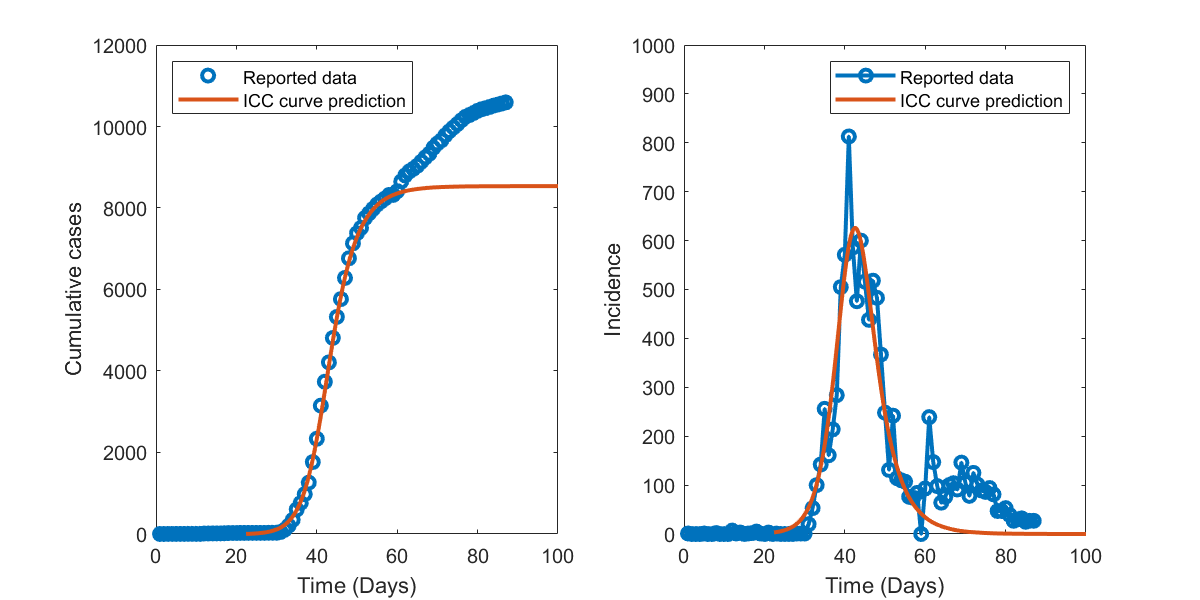

% ICC curve
icc=@(x) ICC(0,x,X(1)^2,X(2)^2,X(3),X(4)); tme=1:1:length(C);
% Parameters
i_start=10; i_align=min(45,length(tme));
% Integrate ICC curve
[t,y] = ode45(@(t,y) icc(y), tme(i_start):0.1:round(length(I_raw)*1.2), ...
    mean(I(i_start-1:i_start+1)));
% Find integration constant by shifting time
t_sw=tme(i_align); %t_sw=tme(i_start+i_sw-1);
i_shft=find(y>C(i_align),1,'first'); t=t-t(i_shft)+t_sw+1/2;
figure(); set(gcf,'Position',[50 50 800 400]);
subplot(1,2,1)
plot(1:dt:length(I_raw),C_raw,'o',t,y,'-','LineWidth',2); xlim([0 100])
xlabel(['Time (' time_unit{1} 's)']); ylabel('Cumulative cases');
legend('Reported data','ICC curve prediction','Location','northwest')
subplot(1,2,2)
plot(1:dt:length(I_raw),I_raw,'o-',t,icc(y),'-','LineWidth',2); xlim([0 100])
xlabel(['Time (' time_unit{1} 's)']); ylabel('Incidence'); ylim([0 1000])
legend('Reported data','ICC curve prediction','Location','northeast')

## Figures 8C & S11

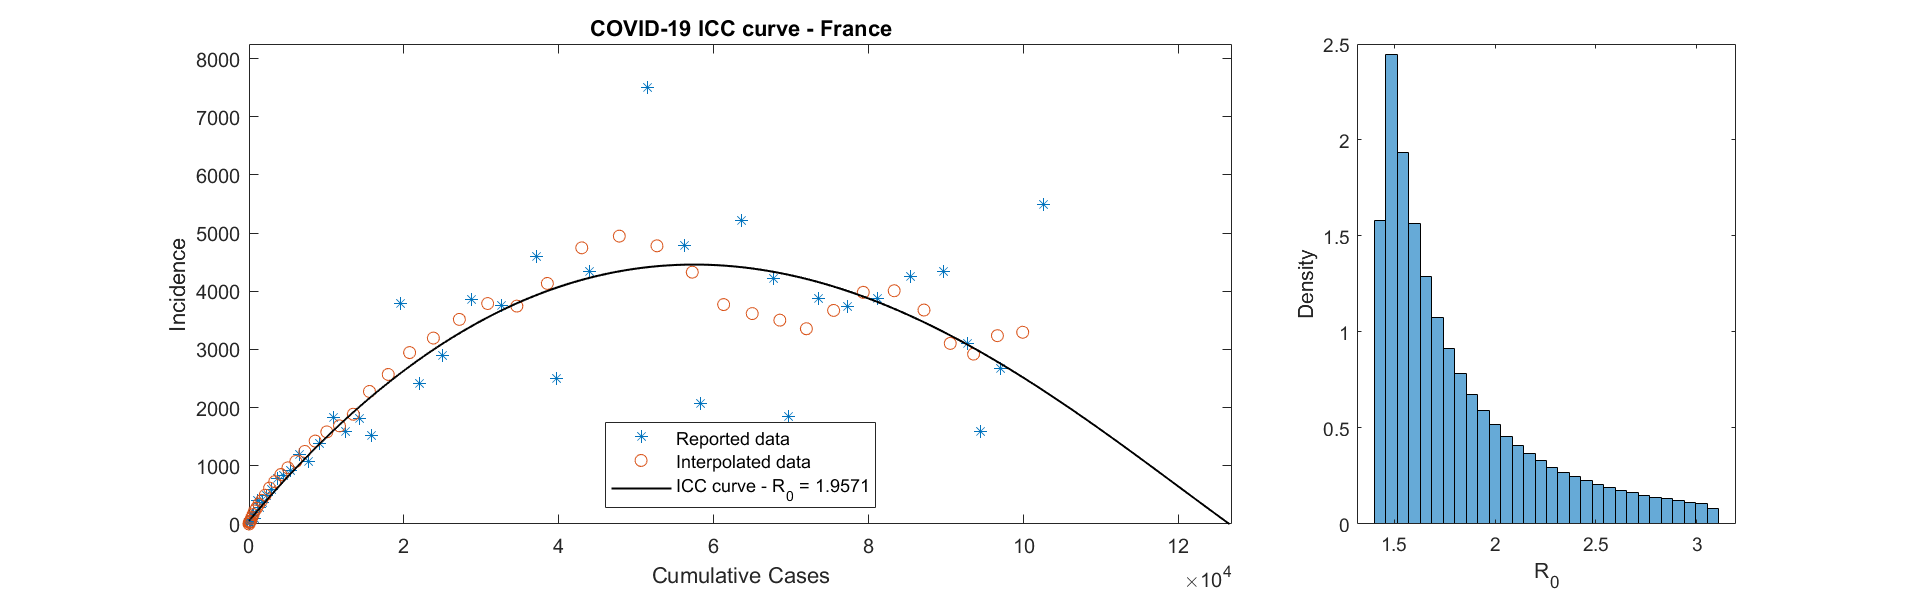

clear variables;
% Read data file
location_name='France'; pathname='./Data_files/'; fname='France.xlsx';
filename=char(strcat(pathname,fname));
[A_raw,txt,~]=xlsread(filename); time_unit=txt(2,1);
i_end_icc=size(A_raw,1); i_st_icc=1;
C_raw=A_raw(1:end,3); I_raw=[1; C_raw(2:end)-C_raw(1:end-1)];
% Smooth and interpolate the cumulative data - reduce the smoothing factor
% (the last argument of find_IC) to make estimates closer to data
smth_factor=6; [~,DC,In_ref,C_ref]=...
    find_IC(C_raw(i_st_icc:i_end_icc),smth_factor);
DIn=DC; DIn(2:end)=DC(2:end)-DC(1:end-1); dt=A_raw(2,1)-A_raw(1,1);
C=(DC(2:end)+DC(1:end-1))/2; I=DIn(2:end)/dt; MI=max([max(I) max(I_raw)]);
% Calculate beta and gamma for different values of N
N_0 = C(end); nval=30000; RM=zeros(1,nval); bt=RM; gm=RM; z=RM;
i_start=1; nc=linspace(N_0+1,4*N_0,nval);     % Reange of values of N
% Note that find_beta_gamma_z uses points between i_start and length(C)
for j=1:nval
    [bt(j),gm(j),RM(j),z(j)]=find_beta_gamma_z(C(i_start:end),...
        I(i_start:end),nc(j));
end
% Optimal value of N
i_m=find(RM==min(RM));
X0=[sqrt(bt(i_m)),sqrt(gm(i_m)),nc(i_m),nc(i_m)*(1-exp(z(i_m)))];
f=@(X) find_err(X,I,C,4);
options = optimset('MaxFunEvals',50000,'MaxIter',20000);
X=fminsearch(f,X0,options);
C_vals=linspace(0,1.5*X(3),500);
I_opt=ICC(0,C_vals,X(1)^2,X(2)^2,X(3),X(4)); I_opt(I_opt<=0)=0;
i_opt_end=find(I_opt(10:end)==0,1,'first')+9;
C_opt_end=round(C_vals(i_opt_end));
% Parameter estimation
k=find(RM<=1.02*f(X)); n_min=min(nc(k)); n_max=max(nc(k));
nc=n_min:1:n_max; bet=nc; gam=nc; zn=nc;
for j=1:length(nc)
    [bet(j),gam(j),~,zn(j)]=find_beta_gamma_z(C,I,nc(j));
end
N=mean(nc); sc=N/DC(end);
figure(); set(gcf,'Position',[0 0 1400 430]);
subplot(1,15,[1,10])
plot(C_raw,I_raw,'*'); hold on; plot(C,I,'o'); xlabel('Cumulative Cases'); 
plot(C_ref*sc,ICC(0,C_ref*sc,X(1)^2,X(2)^2,X(3),X(4)),'k-','LineWidth',1);
hold off; xlim([0 C_opt_end]); ylim([0 1.1*MI]);
ylabel('Incidence'); title(['COVID-19 ICC curve - ' location_name]);
legend('Reported data','Interpolated data',...
    ['ICC curve - R_0 = ' num2str(X(1)^2/X(2)^2)],'Location','south')
subplot(1,15,[12,15])
histogram(bet./gam,30,'Normalization','pdf');
xlabel('R_0'); ylabel('Density');

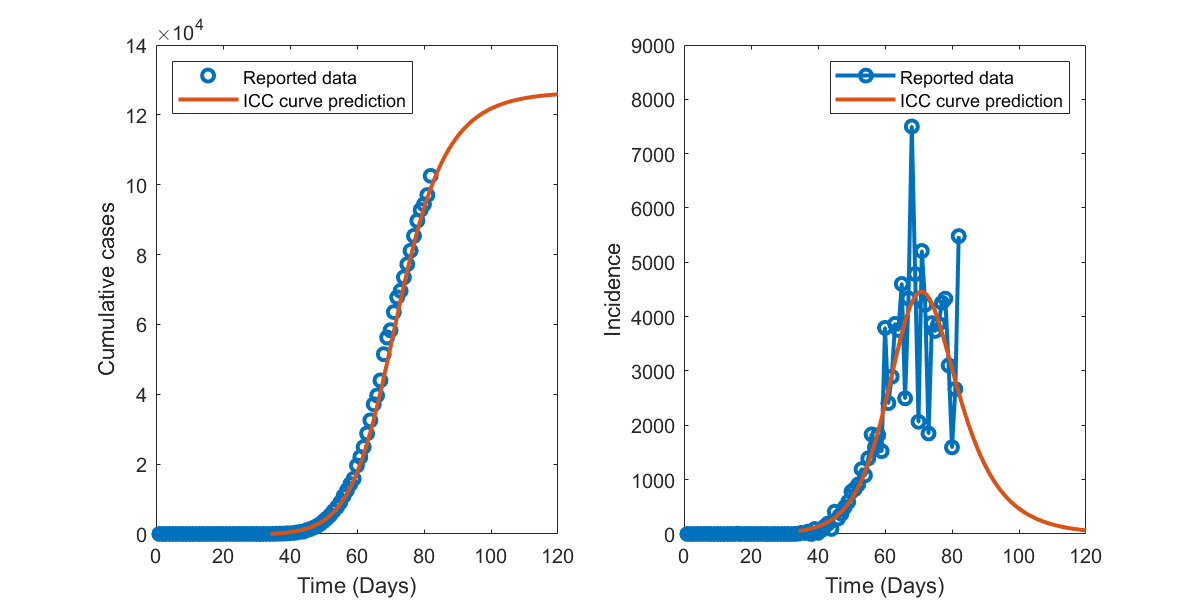

% ICC curve
icc=@(x) ICC(0,x,X(1)^2,X(2)^2,X(3),X(4)); tme=1:1:length(C);
% Parameters
i_start=10; i_align=50;
% Integrate ICC curve
[t,y] = ode45(@(t,y) icc(y), tme(i_start):0.1:round(length(I_raw)*1.2), ...
    mean(I(i_start-1:i_start+1)));
% Find integration constant by shifting time
t_sw=tme(i_align); %t_sw=tme(i_start+i_sw-1);
i_shft=find(y>C(i_align),1,'first'); t=t-t(i_shft)+t_sw+1/2;
figure(); set(gcf,'Position',[50 50 800 400]);
subplot(1,2,1)
plot(1:dt:length(I_raw),C_raw,'o',t,y,'-','LineWidth',2); xlim([0 120])
xlabel(['Time (' time_unit{1} 's)']); ylabel('Cumulative cases');
legend('Reported data','ICC curve prediction','Location','northwest')
subplot(1,2,2)
plot(1:dt:length(I_raw),I_raw,'o-',t,icc(y),'-','LineWidth',2); xlim([0 120])
xlabel(['Time (' time_unit{1} 's)']); ylabel('Incidence'); ylim([0 9000])
legend('Reported data','ICC curve prediction','Location','northeast')

## Function Definitions

### SIR Model

function dy=SIR(~,y,beta,gam,N)

dy=zeros(size(y));
dy(1)=-beta*y(1)*y(2)/N;
dy(2)=beta*y(1)*y(2)/N-gam*y(2);
dy(3)=gam*y(2);
end

### Find_param_Poisson

This code finds the parameters $\beta$ (`bet`), $\gamma$ (`gam`), and $p$ (`z`) for the SIR ICC curve in the presence of Poisson-distributed noise. It also returns the mean and variance of the relative size of the noise.

function [bet,gam,mn,vn,z]=find_param_Poisson(DC,DIn,dt,N)
% Created 5/16/2019 by J. Lega
% Last modified: 4/11/2020

DInN = poissrnd(DIn); DInN(1)=DIn(1); % Noisy incidence
% Enforce same total number of cases at the end of the outbreak
DInN=DInN*DC(end)/sum(DInN);
% Calculate cumulative number of cases
DICCN=cumsum(DInN); 
% Find beta and gamma
C=(DICCN(2:end)+DICCN(1:end-1))/2; I=DInN(2:end)/dt;
[bet,gam,~,z]=find_beta_gamma_z(C,I,N);
% Calculate relative error
err=(DInN-DIn)./DIn; mn=mean(err); vn=var(err);
end

### Find_beta_gamma_z

This function returns estimates of $\beta$, $\gamma$, and $z=\log(\kappa)$ for the SIR model, given ICC data points. It also calculates the RMSE between the data points and the ICC curve obtained from the estimated parameters.

function [bet,gam,RMSE,z]=find_beta_gamma_z(C,I,N)
% C: cumulative cases
% I: corresponding incidence
% N: size of population
% z: log(kappa), where kappa = 1-C(0)/N
% C(0): initial number of cases
%
% Note that small denominator values are likely to lead to numerical
% errors (see Num_error_example.mlx for an example). It is therefore
% recommended to run a search procedure for the minimizer using the values
% calculated here as initial conditions, to increase accuracy.
%
% Created 3/7/2020 by J. Lega
% Last modified 4/19/2020

% Remove data points corresponding to values of C that are bigger than or
% equal to N
I(C>=N)=[]; C(C>=N)=[];

P=1-C./N; U=C/N.*(1-C/N); V=-(1-C/N).*log(1-C/N);
A=sum(U.*P); B=sum(P.^2); D=-sum(V.*P); F=sum(P.*I/N); L=sum(U.^2);
NN=-sum(U.*V); O=sum(U.*I/N); PP=sum(V.^2); Q=-sum(I.*V/N);

z=((-NN*Q+O*PP)*A+(L*Q-NN*O)*D+(-L*PP+NN^2)*F)/...
    ((A*O-F*L)*D-(A^2-B*L)*Q-NN*(B*O-F*A));
bet=((-B*O+F*A)*z^2+(2*O*D-F*NN-A*Q)*z+NN*Q-O*PP)/...
    ((A^2-B*L)*z^2+2*(-A*NN+D*L)*z-L*PP+NN^2);
gam=((-A*O+F*L)*z-L*Q+NN*O)/...
    ((A^2-B*L)*z^2+2*(-A*NN+D*L)*z-L*PP+NN^2);

RMSE=sqrt(mean((ICC(0,C,bet,gam,N,N*(1-exp(z)))-I).^2));
end

### Find_param_Normal

This code finds the parameters $\beta$ (`bet`), $\gamma$ (`gam`), and $p$ (`z`) for the SIR ICC curve in the presence of normally-distributed noise. It also returns the mean and variance of the relative size of the noise.

function [bet,gam,mn,vn,z]=find_param_Normal(DC,DIn,dt,N,noise_size)
% Created 5/17/2019 by J. Lega
% Last modified: 4/11/2020

% Noisy incidence
DInN = DIn.*(1+noise_size*(randn(size(DIn))-0.5));
DInN(1)=DIn(1);
% Enforce same total number of cases at the end of the outbreak
DInN=DInN*DC(end)/sum(DInN);
% Calculate cumulative number of cases
DICCN=cumsum(DInN); 
% Find beta and gamma
C=(DICCN(2:end)+DICCN(1:end-1))/2; I=DInN(2:end)/dt;
[bet,gam,~,z]=find_beta_gamma_z(C,I,N);
% Discard negative values of gamma
if gam < 0
    j_cnt=0;
end
while gam<0 && j_cnt < 100
    j_cnt=j_cnt+1;
    DInN = DIn.*(1+noise_size*(randn(size(DIn))-0.5));
    DInN(1)=DIn(1);
    DInN=DInN*DC(end)/sum(DInN);
    DICCN=cumsum(DInN);
    C=(DICCN(2:end)+DICCN(1:end-1))/2; I=DInN(2:end)/dt;
    [bet,gam,~,z]=find_beta_gamma_z(C,I,N);
end
% Calculate relative error
err=(DInN-DIn)./DIn; mn=mean(err); vn=var(err);
end

### Find_IC

This function takes a time series of cumulative cases and interpolates it to remove the effect of reports when incidence was not updated or when negative incidence was reported.

function [W,C,Growth,Cases]=find_IC(A_raw,smth_factor)
% Created 5/24/2019 by J. Lega
% Modified on 9/19/2019 to include smoothing factor smth_factor
% Last modified 7/7/2020
%
C = A_raw;               % Number of reported cases
W = 1:1:length(C);            % Weeks with new data points
T_max=W(end);
% Define a more refined grid on which to interpolate the data
h=1/28;
Weeks=1:h:T_max;            % Time in TU
Cases=zeros(size(Weeks));   % Number of cases
Growth=zeros(size(Weeks));  % Growth rate
if sum(C) > 0
    % Remove repeated values except zeros and end values
    D=[1; C(2:end)-C(1:end-1)];
    W(D==0 & C~=0 & C~=C(end))=[];
    C(D==0 & C~=0 & C~=C(end))=[];
    % Smooth and then interporlate the data
    Cases=interp1(W,smooth(W,C,smth_factor),Weeks,'pchip');
    % Growth rate
    Growth=[(Cases(2)-Cases(1))/h ...
        (Cases(3:end)-Cases(1:end-2))/2/h ...
        (Cases(end)-Cases(end-1))/h];
    % Set to zero negative values in Cases vector (7/7/2020)
    Growth(Cases<0)=0;
    Cases(Cases<0)=0;
end
W = 1:1:T_max;            % Weeks with new data points
k=ismember(Weeks,W);
C=Cases(k); W=Weeks(k);
% Make sure C does not decrease as a function of time
DC=C(2:end)-C(1:end-1); k=find(DC<0)+1;
while ~isempty(k)
    for j=1:length(k)
        C(k(j))=C(k(j)-1);
    end
    DC=C(2:end)-C(1:end-1); k=find(DC<0)+1;
end
end

### ICC

This function calculates the ICC curve for the SIR model, and includes the initial condition as $C_0 = C(0) = N (1 - \kappa)$. The value of `dy` is set to 0 in regions where $x \ge N$ or if `dy` $< 0$.

function dy=ICC(~,x,bet,gam,N,C0)
% Created 5/24/2019 by J. Lega
% Last modified 4/22/2020
dy=(bet*x+N*gam*log(abs(N-x)/(N-C0))).*(1-x/N);
dy((N-x)<=0)=0;
end

### Find_err

This function calculates the error between the ICC curve with parameters contained in `X` and the data points. It prevents $R_0$ to go above the parameter R0`_max`.

function RMSE=find_err(X,I,C,R0_max)
% Created 2/9/2020 by J. Lega
% Last modified 4/19/2020

% Remove data points corresponding to values of C that are bigger than or
% equal to N = X(3)
I(C>=X(3))=[]; C(C>=X(3))=[];

% Find ICC curve
Ic=ICC(0,C,X(1)^2,X(2)^2,X(3),X(4));

% Return error
RMSE=sqrt(mean((I-Ic).^2))+100000*((X(1)/X(2))^2>R0_max)^2;
end